## SIMULATIONS FOR (k,l)-RESILIENT SYSTEMS

Romain DAGNAS

clear
close all
clc,

% a = 0.071;          % outlet valve coef
% alpha = 320;        % cross sectional area : cm²
% h0 = 12.4;          % working point
% gamma1 = 0.7;       % valve coef
% gamma2 = 0.6;       % valve coef
% k = 3.33;           % pump coef : cm^3 / V second
% n1 = 0.07;          % fraction of the liquid flow of pump 3 going to tank 1
% n2 = 0.05;          % fraction of the liquid flow of pump 4 going to tank 2
% lambda = 3.35;
% lambda1 = 3.35;     % pump 3 coef : cm^3 / V second
% lambda2 = 3.35;     % pump 4 coef : cm^3 / V second
% w1 = 3;             % voltage : V
% w2 = 3;             % voltage : V

a = 4;
alpha = 32;
h0 = 1.5625;
%gamma1 = 0.7;
% 
% gamma2 = 0.5;
% Gamma1 = 0.7;
% Gamma2 = 0.5;
k = 5;
n1 = 0.7;%0.07;
n2 = 0.6;%0.05;
lambda = 5;%0.15;
lambda1 = 0.1;
lambda2 = 0.2;
w1 = 3;%0.15;
w2 = 3;%0.23;

%------TEST----------
a1 = 0.071;
a2 = 0.057;
a3 = 0.071;
a4 = 0.057;
alpha1 = 28;
alpha2 = 32;
alpha3 = 28;
alpha4 = 32;
h10 = 12.26;
h20 = 12.78;
h30 = 1.63;
h40 = 1.41;
gamma1 = 0.7;
gamma2 = 0.6;
k1 = 3.33;
k2 = 3.35;
kc = 0.5; % V / cm
hmax = 20; % cm
g = 981;           % acceleration of gravity : cm / s^2

rho = 997;          % density of liquid (here : water) : kg / m^3


% Gamma_1_a = zeros(1,360);
% for i=1:1:100
%     Gamma_1_a(1,i) = 0.7;
% end
% for i=101:1:360
%     Gamma_1_a(1,i) = 1;
% end
% Gamma_1_a


u=3;



### PETIT


A_base = [-a/(alpha*2*sqrt(h0))];
B_base = [(gamma1*k)/alpha];
C_base = [1; 0; a/(2*sqrt(h0))];
D_base = [0; gamma1*k; 0];

% [NUMbase_1,DENbase_1] = ss2tf(A_base,B_base,C_base,D_base,1);
% [NUMbase_2,DENbase_2] = ss2tf(A_base,B_base,C_base,D_base,2);

SYS_base = ss(A_base,B_base,C_base,D_base);
SYS_tbase = tf(SYS_base);
SYS_tbase_d = c2d(SYS_tbase, 0.1)


SYS_tbase_d =
 
  From input to output...
        0.01091
   1:  ---------
       z - 0.995
 
   2:  3.5
 
        0.01746
   3:  ---------
       z - 0.995
 
Sample time: 0.1 seconds
Discrete-time transfer function.



%figure
%iopzplot(SYS_tbase_d);
%axis([-1.5, 1.5 -1.25 1.25]);

%figure
%step(SYS_tbase_d);

### ZERO-DYN-ATT

A0 = [ -0.0158     0            0.0256      0;
        0          -0.0109      0           0.0178 ;
        0          0            -0.0256     0  ;
        0          0            0           -0.0178 ];

B0 = [ 0.0482     0;
        0         0.0350;
        0         0.0775;
        0.0559    0 ];

C0 = [ 0.5  0   0 0;
       0    0.5 0 0; ];

D0 = [ 0 0;
       0 0;];

### (0,1)-RESILIENT / (1,1)-RESILIENT


% (0,1)-RESILIENT / (1,1)

%       ==> 4 capteurs pour le niveau de liquide
%       ==> 4 actionneurs


A11 = [ -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) )      0;
        0                           -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) ) ;
        0                           0                           -a/( alpha*2*sqrt(h0) ) 	0  ;
        0                           0                           0                           -a/( alpha*2*sqrt(h0) ) ];

B11 = [ gamma1*k/alpha      0;
        0                   gamma2*k/alpha;
        0                   (1-gamma2)*k/alpha;
        (1-gamma1)*k/alpha    0 ];

C11 = [ 1 0 0 0;
        0 1 0 0;
        0 0 1 0;
        0 0 0 1 ];

D11 = [ 0 0;
        0 0;
        0 0;
        0 0 ];
    

%TEST
% A11 = [ -a1/( alpha1*2*sqrt(h1) )     0                           a3/( alpha1*2*sqrt(h3) )      0;
%         0                           -a2/( alpha2*2*sqrt(h2) )     0                           a4/( alpha2*2*sqrt(h4) ) ;
%         0                           0                           -a3/( alpha3*2*sqrt(h3) ) 	0  ;
%         0                           0                           0                           -a4/( alpha4*2*sqrt(h4) ) ];
% 
% B11 = [ gamma1*k1/alpha1      0;
%         0                   gamma2*k2/alpha2;
%         0                   (1-gamma2)*k2/alpha3;
%         (1-gamma1)*k1/alpha4    0 ];
    
      

### (1,2)-RESILIENT


% (1,2)-RESILIENT

%       ==> + 4 capteurs pour le débit d'entrée

A12 = [ -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) )      0;
        0                           -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) );
        0                           0                           -a/( alpha*2*sqrt(h0) )     0;
        0                           0                           0                           -a/( alpha*2*sqrt(h0) ) ];

B12 = [ gamma1*k/alpha      0;
        0                   gamma2*k/alpha;
        0                   (1-gamma2)*k/alpha;
        (1-gamma1)*k/alpha    0 ];

C12 = [ 1 0 0 0;
        0 0 0 0;
        0 1 0 0;
        0 0 0 0;
        0 0 1 0;
        0 0 0 0;
        0 0 0 1;
        0 0 0 0 ];

D12 = [ 0               0;
        gamma1*k        0;
        0               0;
        0               gamma2*k;
        0               0;
        0               (1-gamma2)*k;
        0               0;
        (1-gamma1)*k    0 ];

    
        

### (2,2)-RESILIENT


% (2,2)-RESILIENT


A22 = [ -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) )      0;
        0                           -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) );
        0                           0                           -a/( alpha*2*sqrt(h0) )     0;
        0                           0                           0                           -a/( alpha*2*sqrt(h0) ) ];

B22 = [ gamma1*k/alpha      0                   n1*lambda*w1/alpha      0;
        0                   gamma2*k/alpha      0                       n2*lambda*w2/alpha;
        0                   (1-gamma2)*k/alpha  0                       (1-n2)*lambda*w2/alpha;
        (1-gamma1)*k/alpha  0                   (1-n1)*lambda*w1/alpha  0 ];
    
C22 = [ 1 0 0 0;
        0 0 0 0;
        0 1 0 0;
        0 0 0 0;
        0 0 1 0;
        0 0 0 0;
        0 0 0 1;
        0 0 0 0 ];
    
D22 = [ 0                   0                   0                       0;
        gamma1*k            0                   n1*lambda*w1            0;
        0                   0                   0                       0;
        0                   gamma2*k            0                       n2*lambda*w2;
        0                   0                   0                       0;
        0                   (1-gamma2)*k        0                       (1-n2)*lambda*w2;
        0                   0                   0                       0;
        (1-gamma1)*k        0                   (1-n1)*lambda*w1        0 ];
    
    

### (1,3)-RESILIENT


% (1,3)-RESILIENT


A13 = [ -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) )      0;
        0                           -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) );
        0                           0                           -a/( alpha*2*sqrt(h0) )     0;
        0                           0                           0                           -a/( alpha*2*sqrt(h0) ) ];

B13 = [ gamma1*k/alpha      0;
        0                   gamma2*k/alpha;
        0                   (1-gamma2)*k/alpha;
        (1-gamma1)*k/alpha    0 ];

    
C13 = [  1               0                   0                   0;
         0               0                   0                   0;
         a/2*sqrt(h0)    0                   0                   0;
         0               1                   0                   0;
         0               0                   0                   0;
         0               a/2*sqrt(h0)        0                   0;
         0               0                   1                   0;
         0               0                   0                   0;
         0               0                   a/2*sqrt(h0)        0;
         0               0                   0                   1;
         0               0                   0                   0;
         0               0                   0                   a/2*sqrt(h0) ];
    
D13 = [  0               0;
         gamma1*k        0;
         0               0;
         0               0;
         0               gamma2*k;
         0               0;
         0               0;
         0               (1-gamma2)*k;
         0               0;
         0               0;
         (1-gamma1)*k    0;
         0               0 ];
    
    
        
        

### (2,3)-RESILIENT


% (2,3)-RESILIENT   
 

A23 = [ -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) )      0;
         0                           -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) );
         0                           0                           -a/( alpha*2*sqrt(h0) )     0;
         0                           0                           0                           -a/( alpha*2*sqrt(h0) ) ];
 
 B23 = [ gamma1*k/alpha      0                   n1*lambda*w1/alpha      0;
         0                   gamma2*k/alpha      0                       n2*lambda*w2/alpha;
         0                   (1-gamma2)*k/alpha  0                       (1-n2)*lambda*w2/alpha;
         (1-gamma1)*k/alpha  0                   (1-n1)*lambda*w1/alpha  0 ];
 
 
 C23 = [   1               0                   0                   0;
           0               0                   0                   0;
           a/2*sqrt(h0)    0                   0                   0;
           0               1                   0                   0;
           0               0                   0                   0;
           0               a/2*sqrt(h0)        0                   0;
           0               0                   1                   0;
           0               0                   0                   0;
           0               0                   a/2*sqrt(h0)        0;
           0               0                   0                   1;
           0               0                   0                   0;
           0               0                   0                   a/2*sqrt(h0) ];;
     
 
 D23 = [   0               0                   0                       0;
                                gamma1*k        0                   n1*lambda1*w1           0;
                                0               0                   0                       0;
                                0               0                   0                       0;
                                0               gamma2*k            0                       n2*lambda2*w2;
                                0               0                   0                       0;
                                0               0                   0                       0;
                                0               (1-gamma2)*k        0                       (1-n2)*lambda2*w2;
                                0               0                   0                       0;
                                0               0                   0                       0;
                                (1-gamma1)*k    0                   (1-n1)*lambda1*w1       0;
                                0               0                   0                       0 ];

     
A23_plus_liquid_pressure = [    -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) )      0;
                                0                           -a/( alpha*2*sqrt(h0) )     0                           a/( alpha*2*sqrt(h0) );
                                0                           0                           -a/( alpha*2*sqrt(h0) )     0;
                                0                           0                           0                           -a/( alpha*2*sqrt(h0) ) ];
 
 B23_plus_liquid_pressure = [   gamma1*k/alpha      0                   n1*lambda*w1/alpha      0;
                                0                   gamma2*k/alpha      0                       n2*lambda*w2/alpha;
                                0                   (1-gamma2)*k/alpha  0                       (1-n2)*lambda*w2/alpha;
                                (1-gamma1)*k/alpha  0                   (1-n1)*lambda*w1/alpha  0 ];
 
 
 C23_plus_liquid_pressure = [ 1               0                   0                   0 ;
         0               0                   0                   0;
         a/2*sqrt(h0)    0                   0                   0;
         rho*g           0                   0                   0;
         0               1                   0                   0;
         0               0                   0                   0;
         0               a/2*sqrt(h0)        0                   0;
         0               rho*g               0                   0;
         0               0                   1                   0;
         0               0                   0                   0;
         0               0                   a/2*sqrt(h0)        0;
         0               0                   rho*g               0;
         0               0                   0                   1;
         0               0                   0                   0;
         0               0                   0                   a/2*sqrt(h0)
         0               0                   0                   rho*g ];
     
 
 D23_plus_liquid_pressure = [ 0               0                   0                       0;
         gamma1*k        0                   n1*lambda1*w1           0;
         0               0                   0                       0;
         0               0                   0                       0;
         0               0                   0                       0;
         0               gamma2*k            0                       n2*lambda2*w2;
         0               0                   0                       0;
         0               0                   0                       0;
         0               0                   0                       0;
         0               (1-gamma2)*k        0                       (1-n2)*lambda2*w2;
         0               0                   0                       0;
         0               0                   0                       0;
         0               0                   0                       0;
         (1-gamma1)*k    0                   (1-n1)*lambda1*w1       0;
         0               0                   0                       0;
         0               0                   0                       0 ];

### (1,4)-RESILIENT      

% (2,4)-RESILIENT  
 
% A14 = [zeros(4,4) A13;
%        zeros(4,4) A13];
A14 = [A13          A13;
       zeros(4,4)   A13];

B14 = [B13 zeros(4,2);
       zeros(4,2) B13];
   
C14 = [C13 zeros(12,4);
       zeros(12,4) C13];

D14 = [D13 zeros(12,2);
       zeros(12,2) D13];

### (2,4)-RESILIENT      

% (2,4)-RESILIENT  
 
% A24 = [A23 zeros(4,4);
%        zeros(4,4) A23];

% A1 = zeros(4,4);
% A2 = zeros(4,4);
% 
% for i=1:1:4
%     for j=1:1:4
%         A1(i,j) = A23(i,j)+0.1;
%         A2(i,j) = A23(i,j)-0.1;
%     end
% end

A24 = [A23          A23;
       zeros(4,4)   A23];

B24 = [B23 zeros(4,4);
       zeros(4,4) B23];
   
C24 = [C23 zeros(12,4);
       zeros(12,4) C23];

D24 = [D23 zeros(12,4);
       zeros(12,4) D23];

### TRANSFER FUNCTIONS

% ZERO-DYN-ATT

SYS0 = ss(A0,B0,C0,D0);
SYS_t0 = tf(SYS0);
SYS_t0_d = c2d(SYS_t0, 0.1);

ua0 = zeros(2,360);

for t=1:1:360
    ua0(:,t) = [0.7316; -0.6817;]*exp(0.0127*t);
end
ua0

ua0 =     0.7410    0.7504    0.7600    0.7697    0.7796    0.7895    0.7996    0.8098    0.8202    0.8307    0.8413    0.8520    0.8629    0.8740    0.8851    0.8964    0.9079    0.9195    0.9313    0.9432    0.9552    0.9674    0.9798    0.9923    1.0050    1.0178    1.0308    1.0440    1.0574    1.0709    1.0846    1.0984    1.1125    1.1267    1.1411    1.1557    1.1704    1.1854    1.2005    1.2159    1.2314    1.2472    1.2631    1.2793    1.2956    1.3122    1.3289    1.3459    1.3631    1.3805
   -0.6904   -0.6992   -0.7082   -0.7172   -0.7264   -0.7357   -0.7451   -0.7546   -0.7642   -0.7740   -0.7839   -0.7939   -0.8041   -0.8143   -0.8248   -0.8353   -0.8460   -0.8568   -0.8677   -0.8788   -0.8901   -0.9014   -0.9130   -0.9246   -0.9364   -0.9484   -0.9605   -0.9728   -0.9852   -0.9978   -1.0106   -1.0235   -1.0366   -1.0498   -1.0633   -1.0768   -1.0906   -1.1045   -1.1187   -1.1330   -1.1474   -1.1621   -1.1770   -1.1920   -1.2072   -1.2227   -1.2383   -1.2541   -1.2701   

   

% (1,1)-resilient

[NUM11_1,DEN11_1] = ss2tf(A11,B11,C11,D11,1);
[NUM11_2,DEN11_2] = ss2tf(A11,B11,C11,D11,2);

SYS11 = ss(A11,B11,C11,D11);
SYS_t11 = tf(SYS11);
SYS_t11_d = c2d(SYS_t11, 0.1)


SYS_t11_d =
 
  From input 1 to output...
        0.01091
   1:  ---------
       z - 0.995
 
       1.168e-05 z + 1.164e-05
   2:  -----------------------
         z^2 - 1.99 z + 0.99
 
   3:  0
 
       0.004676
   4:  ---------
       z - 0.995
 
  From input 2 to output...
       1.557e-05 z + 1.552e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
       0.009352
   2:  ---------
       z - 0.995
 
       0.006234
   3:  ---------
       z - 0.995
 
   4:  0
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%TRANSFER_FUNCTION = [   0.1094/()
%                            ]
Z11 = zero(SYS_t11_d(1,1));
P11 = real(pole(SYS_t11_d(1,1)));
Z21 = zero(SYS_t11_d(2,1));
P21 = real(pole(SYS_t11_d(2,1)));
Z31 = zero(SYS_t11_d(3,1));
P31 = real(pole(SYS_t11_d(3,1)));
Z41 = zero(SYS_t11_d(4,1));
P41 = real(pole(SYS_t11_d(4,1)));
Z12 = zero(SYS_t11_d(1,2));
P12 = real(pole(SYS_t11_d(1,2)));
Z22 = zero(SYS_t11_d(2,2));
P22 = real(pole(SYS_t11_d(2,2)));
Z32 = zero(SYS_t11_d(3,2));
P32 = real(pole(SYS_t11_d(3,2)));
Z42 = zero(SYS_t11_d(4,2));
P42 = real(pole(SYS_t11_d(4,2)));
ZERO_11 = [Z11; Z21; Z31; Z41; Z12; Z22; Z32; Z42;]

ZERO_11 =    -0.9967
   -0.9967


POLE_11 = abs([P11; P21; P31; P41; P12; P22; P32; P42;])

POLE_11 =     0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950



% svd()
% 
%u_a = zeros(1,360);
final = zeros(1,360);
c = [   100;
        300;
        520;
        874;
        100;
        456;
        200;
        144; ];
v_m = [ 0.05;
        0.05;      ];
    
        
% syms s
% eqn = (0.002344 / (s^2 + 0.1*s + 0.0025)) == 0;
% 
% 
% sol = solve(eqn, s);
% sol



u_a=exp((1:100)*0.05);


u_a

u_a =     1.0513    1.1052    1.1618    1.2214    1.2840    1.3499    1.4191    1.4918    1.5683    1.6487    1.7333    1.8221    1.9155    2.0138    2.1170    2.2255    2.3396    2.4596    2.5857    2.7183    2.8577    3.0042    3.1582    3.3201    3.4903    3.6693    3.8574    4.0552    4.2631    4.4817    4.7115    4.9530    5.2070    5.4739    5.7546    6.0496    6.3598    6.6859    7.0287    7.3891    7.7679    8.1662    8.5849    9.0250    9.4877    9.9742   10.4856   11.0232   11.5883   12.1825




% figure
% pzplot(SYS_t11)
% (1,2)-resilient

[NUM12_1,DEN12_1] = ss2tf(A12,B12,C12,D12,1);
[NUM12_2,DEN12_2] = ss2tf(A12,B12,C12,D12,2);

SYS12 = ss(A12,B12,C12,D12);
SYS_t12 = tf(SYS12)


SYS_t12 =
 
  From input 1 to output...
        0.1094
   1:  --------
       s + 0.05
 
   2:  3.5
 
             0.002344
   3:  --------------------
       s^2 + 0.1 s + 0.0025
 
   4:  0
 
   5:  0
 
   6:  0
 
       0.04688
   7:  --------
       s + 0.05
 
   8:  1.5
 
  From input 2 to output...
             0.003125
   1:  --------------------
       s^2 + 0.1 s + 0.0025
 
   2:  0
 
       0.09375
   3:  --------
       s + 0.05
 
   4:  3
 
        0.0625
   5:  --------
       s + 0.05
 
   6:  2
 
   7:  0
 
   8:  0
 
Continuous-time transfer function.



SYS_t12_d = c2d(SYS_t12, 0.1)


SYS_t12_d =
 
  From input 1 to output...
        0.01091
   1:  ---------
       z - 0.995
 
   2:  3.5
 
       1.168e-05 z + 1.164e-05
   3:  -----------------------
         z^2 - 1.99 z + 0.99
 
   4:  0
 
   5:  0
 
   6:  0
 
       0.004676
   7:  ---------
       z - 0.995
 
   8:  1.5
 
  From input 2 to output...
       1.557e-05 z + 1.552e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
   2:  0
 
       0.009352
   3:  ---------
       z - 0.995
 
   4:  3
 
       0.006234
   5:  ---------
       z - 0.995
 
   6:  2
 
   7:  0
 
   8:  0
 
Sample time: 0.1 seconds
Discrete-time transfer function.



% (2,2)-resilient

[NUM22_1,DEN22_1] = ss2tf(A22,B22,C22,D22,1);
[NUM22_2,DEN22_2] = ss2tf(A22,B22,C22,D22,2);

SYS22 = ss(A22,B22,C22,D22);
SYS_t22 = tf(SYS22);
SYS_t22_d = c2d(SYS_t22, 0.1)


SYS_t22_d =
 
  From input 1 to output...
        0.01091
   1:  ---------
       z - 0.995
 
   2:  3.5
 
       1.168e-05 z + 1.164e-05
   3:  -----------------------
         z^2 - 1.99 z + 0.99
 
   4:  0
 
   5:  0
 
   6:  0
 
       0.004676
   7:  ---------
       z - 0.995
 
   8:  1.5
 
  From input 2 to output...
       1.557e-05 z + 1.552e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
   2:  0
 
       0.009352
   3:  ---------
       z - 0.995
 
   4:  3
 
       0.006234
   5:  ---------
       z - 0.995
 
   6:  2
 
   7:  0
 
   8:  0
 
  From input 3 to output...
        0.03273
   1:  ---------
       z - 0.995
 
   2:  10.5
 
       3.504e-05 z + 3.492e-05
   3:  -----------------------
         z^2 - 1.99 z + 0.99
 
   4:  0
 
   5:  0
 
   6:  0
 
        0.01403
   7:  ---------
       z - 0.995
 
   8:  4.5
 
  From input 4 to output...
       4.672e-05 z + 4.656e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
   2:  0
 
    

Z_22_11 = zero(SYS_t22_d(1,1));
P_22_11 = real(pole(SYS_t22_d(1,1)));
Z_22_21 = zero(SYS_t22_d(2,1));
P_22_21 = real(pole(SYS_t22_d(2,1)));
Z_22_31 = zero(SYS_t22_d(3,1));
P_22_31 = real(pole(SYS_t22_d(3,1)));
Z_22_41 = zero(SYS_t22_d(4,1));
P_22_41 = real(pole(SYS_t22_d(4,1)));
Z_22_51 = zero(SYS_t22_d(5,1));
P_22_51 = real(pole(SYS_t22_d(5,1)));
Z_22_61 = zero(SYS_t22_d(6,1));
P_22_61 = real(pole(SYS_t22_d(6,1)));
Z_22_71 = zero(SYS_t22_d(7,1));
P_22_71 = real(pole(SYS_t22_d(7,1)));
Z_22_81 = zero(SYS_t22_d(8,1));
P_22_81 = real(pole(SYS_t22_d(8,1)));

Z_22_12 = zero(SYS_t22_d(1,2));
P_22_12 = real(pole(SYS_t22_d(1,2)));
Z_22_22 = zero(SYS_t22_d(2,2));
P_22_22 = real(pole(SYS_t22_d(2,2)));
Z_22_32 = zero(SYS_t22_d(3,2));
P_22_32 = real(pole(SYS_t22_d(3,2)));
Z_22_42 = zero(SYS_t22_d(4,2));
P_22_42 = real(pole(SYS_t22_d(4,2)));
Z_22_52 = zero(SYS_t22_d(5,2));
P_22_52 = real(pole(SYS_t22_d(5,2)));
Z_22_62 = zero(SYS_t22_d(6,2));
P_22_62 = real(pole(SYS_t22_d(6,2)));
Z_22_72 = zero(SYS_t22_d(7,2));
P_22_72 = real(pole(SYS_t22_d(7,2)));
Z_22_82 = zero(SYS_t22_d(8,2));
P_22_82 = real(pole(SYS_t22_d(8,2)));

Z_22_13 = zero(SYS_t22_d(1,3));
P_22_13 = real(pole(SYS_t22_d(1,3)));
Z_22_23 = zero(SYS_t22_d(2,3));
P_22_23 = real(pole(SYS_t22_d(2,3)));
Z_22_33 = zero(SYS_t22_d(3,3));
P_22_33 = real(pole(SYS_t22_d(3,3)));
Z_22_43 = zero(SYS_t22_d(4,3));
P_22_43 = real(pole(SYS_t22_d(4,3)));
Z_22_53 = zero(SYS_t22_d(5,3));
P_22_53 = real(pole(SYS_t22_d(5,3)));
Z_22_63 = zero(SYS_t22_d(6,3));
P_22_63 = real(pole(SYS_t22_d(6,3)));
Z_22_73 = zero(SYS_t22_d(7,3));
P_22_73 = real(pole(SYS_t22_d(7,3)));
Z_22_83 = zero(SYS_t22_d(8,3));
P_22_83 = real(pole(SYS_t22_d(8,3)));

Z_22_14 = zero(SYS_t22_d(1,4));
P_22_14 = real(pole(SYS_t22_d(1,4)));
Z_22_24 = zero(SYS_t22_d(2,4));
P_22_24 = real(pole(SYS_t22_d(2,4)));
Z_22_34 = zero(SYS_t22_d(3,4));
P_22_34 = real(pole(SYS_t22_d(3,4)));
Z_22_44 = zero(SYS_t22_d(4,4));
P_22_44 = real(pole(SYS_t22_d(4,4)));
Z_22_54 = zero(SYS_t22_d(5,4));
P_22_54 = real(pole(SYS_t22_d(5,4)));
Z_22_64 = zero(SYS_t22_d(6,4));
P_22_64 = real(pole(SYS_t22_d(6,4)));
Z_22_74 = zero(SYS_t22_d(7,4));
P_22_74 = real(pole(SYS_t22_d(7,4)));
Z_22_84 = zero(SYS_t22_d(8,4));
P_22_84 = real(pole(SYS_t22_d(8,4)));

ZEROS_22 =  [Z_22_11; Z_22_21; Z_22_31; Z_22_41; Z_22_51; Z_22_61; Z_22_71; Z_22_81; Z_22_12; Z_22_22; Z_22_32; Z_22_42; Z_22_52; Z_22_62; Z_22_72; Z_22_82; Z_22_13; Z_22_23; Z_22_33; Z_22_43; Z_22_53; Z_22_63; Z_22_73; Z_22_83; Z_22_14; Z_22_24; Z_22_34; Z_22_44; Z_22_54; Z_22_64; Z_22_74; Z_22_84; ]

ZEROS_22 =    -0.9967
   -0.9967
   -0.9967
   -0.9967


POLES_22 =  [P_22_11; P_22_21; P_22_31; P_22_41; P_22_51; P_22_61; P_22_71; P_22_81; P_22_12; P_22_22; P_22_32; P_22_42; P_22_52; P_22_62; P_22_72; P_22_82; P_22_13; P_22_23; P_22_33; P_22_43; P_22_53; P_22_63; P_22_73; P_22_83; P_22_14; P_22_24; P_22_34; P_22_44; P_22_54; P_22_64; P_22_74; P_22_84; ]

POLES_22 =     0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950



% (1,3)-resilient

[NUM13_1,DEN13_1] = ss2tf(A13,B13,C13,D13,1);
[NUM13_2,DEN13_2] = ss2tf(A13,B13,C13,D13,2);

SYS13 = ss(A13,B13,C13,D13);
SYS_t13 = tf(SYS13);
SYS_t13_d = c2d(SYS_t13, 0.1)


SYS_t13_d =
 
  From input 1 to output...
        0.01091
   1:  ---------
       z - 0.995
 
   2:  3.5
 
        0.02728
   3:  ---------
       z - 0.995
 
       1.168e-05 z + 1.164e-05
   4:  -----------------------
         z^2 - 1.99 z + 0.99
 
   5:  0
 
       2.92e-05 z + 2.91e-05
   6:  ---------------------
        z^2 - 1.99 z + 0.99
 
   7:  0
 
   8:  0
 
   9:  0
 
        0.004676
   10:  ---------
        z - 0.995
 
   11:  1.5
 
         0.01169
   12:  ---------
        z - 0.995
 
  From input 2 to output...
       1.557e-05 z + 1.552e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
   2:  0
 
       3.893e-05 z + 3.88e-05
   3:  ----------------------
        z^2 - 1.99 z + 0.99
 
       0.009352
   4:  ---------
       z - 0.995
 
   5:  3
 
        0.02338
   6:  ---------
       z - 0.995
 
       0.006234
   7:  ---------
       z - 0.995
 
   8:  2
 
        0.01559
   9:  ---------
       z - 0.995
 
   10:  0
 
   11:  0
 
   12:  0
 
Sam

% (1,4)-resilient

[NUM14_1,DEN14_1] = ss2tf(A14,B14,C14,D14,1);
[NUM14_2,DEN14_2] = ss2tf(A14,B14,C14,D14,2);

SYS14 = ss(A14,B14,C14,D14);
SYS_t14 = tf(SYS14);
SYS_t14_d = c2d(SYS_t14, 0.1)


SYS_t14_d =
 
  From input 1 to output...
        0.01091
   1:  ---------
       z - 0.995
 
   2:  3.5
 
        0.02728
   3:  ---------
       z - 0.995
 
       1.168e-05 z + 1.164e-05
   4:  -----------------------
         z^2 - 1.99 z + 0.99
 
   5:  0
 
       2.92e-05 z + 2.91e-05
   6:  ---------------------
        z^2 - 1.99 z + 0.99
 
   7:  0
 
   8:  0
 
   9:  0
 
        0.004676
   10:  ---------
        z - 0.995
 
   11:  1.5
 
         0.01169
   12:  ---------
        z - 0.995
 
   13:  0
 
   14:  0
 
   15:  0
 
   16:  0
 
   17:  0
 
   18:  0
 
   19:  0
 
   20:  0
 
   21:  0
 
   22:  0
 
   23:  0
 
   24:  0
 
  From input 2 to output...
       1.557e-05 z + 1.552e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
   2:  0
 
       3.893e-05 z + 3.88e-05
   3:  ----------------------
        z^2 - 1.99 z + 0.99
 
       0.009352
   4:  ---------
       z - 0.995
 
   5:  3
 
        0.02338
   6:  ---------
       z - 0.995
 
       0.0

% (2,3)-resilient

[NUM23_1,DEN23_1] = ss2tf(A23,B23,C23,D23,1);
[NUM23_2,DEN23_2] = ss2tf(A23,B23,C23,D23,2);

SYS23 = ss(A23,B23,C23,D23);
SYS_t23 = tf(SYS23);
SYS_t23_d = c2d(SYS_t23, 0.1)


SYS_t23_d =
 
  From input 1 to output...
        0.01091
   1:  ---------
       z - 0.995
 
   2:  3.5
 
        0.02728
   3:  ---------
       z - 0.995
 
       1.168e-05 z + 1.164e-05
   4:  -----------------------
         z^2 - 1.99 z + 0.99
 
   5:  0
 
       2.92e-05 z + 2.91e-05
   6:  ---------------------
        z^2 - 1.99 z + 0.99
 
   7:  0
 
   8:  0
 
   9:  0
 
        0.004676
   10:  ---------
        z - 0.995
 
   11:  1.5
 
         0.01169
   12:  ---------
        z - 0.995
 
  From input 2 to output...
       1.557e-05 z + 1.552e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
   2:  0
 
       3.893e-05 z + 3.88e-05
   3:  ----------------------
        z^2 - 1.99 z + 0.99
 
       0.009352
   4:  ---------
       z - 0.995
 
   5:  3
 
        0.02338
   6:  ---------
       z - 0.995
 
       0.006234
   7:  ---------
       z - 0.995
 
   8:  2
 
        0.01559
   9:  ---------
       z - 0.995
 
   10:  0
 
   11:  0
 
   12:  0
 
  F

% p23_61=[1 -1.99 0.99];
% roots(p23_61)


Z_23_11 = zero(SYS_t23_d(1,1));
P_23_11 = real(pole(SYS_t23_d(1,1)));
Z_23_21 = zero(SYS_t23_d(2,1));
P_23_21 = real(pole(SYS_t23_d(2,1)));
Z_23_31 = zero(SYS_t23_d(3,1));
P_23_31 = real(pole(SYS_t23_d(3,1)));
Z_23_41 = zero(SYS_t23_d(4,1));
P_23_41 = real(pole(SYS_t23_d(4,1)));
Z_23_51 = zero(SYS_t23_d(5,1));
P_23_51 = real(pole(SYS_t23_d(5,1)));
Z_23_61 = zero(SYS_t23_d(6,1));
P_23_61 = real(pole(SYS_t23_d(6,1)));
Z_23_71 = zero(SYS_t23_d(7,1));
P_23_71 = real(pole(SYS_t23_d(7,1)));
Z_23_81 = zero(SYS_t23_d(8,1));
P_23_81 = real(pole(SYS_t23_d(8,1)));
Z_23_91 = zero(SYS_t23_d(9,1));
P_23_91 = real(pole(SYS_t23_d(9,1)));
Z_23_101 = zero(SYS_t23_d(10,1));
P_23_101 = real(pole(SYS_t23_d(10,1)));
Z_23_111 = zero(SYS_t23_d(11,1));
P_23_111 = real(pole(SYS_t23_d(11,1)));
Z_23_121 = zero(SYS_t23_d(12,1));
P_23_121 = real(pole(SYS_t23_d(12,1)));

Z_23_12 = zero(SYS_t23_d(1,2));
P_23_12 = real(pole(SYS_t23_d(1,2)));
Z_23_22 = zero(SYS_t23_d(2,2));
P_23_22 = real(pole(SYS_t23_d(2,2)));
Z_23_32 = zero(SYS_t23_d(3,2));
P_23_32 = real(pole(SYS_t23_d(3,2)));
Z_23_42 = zero(SYS_t23_d(4,2));
P_23_42 = real(pole(SYS_t23_d(4,2)));
Z_23_52 = zero(SYS_t23_d(5,2));
P_23_52 = real(pole(SYS_t23_d(5,2)));
Z_23_62 = zero(SYS_t23_d(6,2));
P_23_62 = real(pole(SYS_t23_d(6,2)));
Z_23_72 = zero(SYS_t23_d(7,2));
P_23_72 = real(pole(SYS_t23_d(7,2)));
Z_23_82 = zero(SYS_t23_d(8,2));
P_23_82 = real(pole(SYS_t23_d(8,2)));
Z_23_92 = zero(SYS_t23_d(9,2));
P_23_92 = real(pole(SYS_t23_d(9,2)));
Z_23_102 = zero(SYS_t23_d(10,2));
P_23_102 = real(pole(SYS_t23_d(10,2)));
Z_23_112 = zero(SYS_t23_d(11,2));
P_23_112 = real(pole(SYS_t23_d(11,2)));
Z_23_122 = zero(SYS_t23_d(12,2));
P_23_122 = real(pole(SYS_t23_d(12,2)));

Z_23_13 = zero(SYS_t23_d(1,3));
P_23_13 = real(pole(SYS_t23_d(1,3)));
Z_23_23 = zero(SYS_t23_d(2,3));
P_23_23 = real(pole(SYS_t23_d(2,3)));
Z_23_33 = zero(SYS_t23_d(3,3));
P_23_33 = real(pole(SYS_t23_d(3,3)));
Z_23_43 = zero(SYS_t23_d(4,3));
P_23_43 = real(pole(SYS_t23_d(4,3)));
Z_23_53 = zero(SYS_t23_d(5,3));
P_23_53 = real(pole(SYS_t23_d(5,3)));
Z_23_63 = zero(SYS_t23_d(6,3));
P_23_63 = real(pole(SYS_t23_d(6,3)));
Z_23_73 = zero(SYS_t23_d(7,3));
P_23_73 = real(pole(SYS_t23_d(7,3)));
Z_23_83 = zero(SYS_t23_d(8,3));
P_23_83 = real(pole(SYS_t23_d(8,3)));
Z_23_93 = zero(SYS_t23_d(9,3));
P_23_93 = real(pole(SYS_t23_d(9,3)));
Z_23_103 = zero(SYS_t23_d(10,3));
P_23_103 = real(pole(SYS_t23_d(10,3)));
Z_23_113 = zero(SYS_t23_d(11,3));
P_23_113 = real(pole(SYS_t23_d(11,3)));
Z_23_123 = zero(SYS_t23_d(12,3));
P_23_123 = real(pole(SYS_t23_d(12,3)));

Z_23_14 = zero(SYS_t23_d(1,4));
P_23_14 = real(pole(SYS_t23_d(1,4)));
Z_23_24 = zero(SYS_t23_d(2,4));
P_23_24 = real(pole(SYS_t23_d(2,4)));
Z_23_34 = zero(SYS_t23_d(3,4));
P_23_34 = real(pole(SYS_t23_d(3,4)));
Z_23_44 = zero(SYS_t23_d(4,4));
P_23_44 = real(pole(SYS_t23_d(4,4)));
Z_23_54 = zero(SYS_t23_d(5,4));
P_23_54 = real(pole(SYS_t23_d(5,4)));
Z_23_64 = zero(SYS_t23_d(6,4));
P_23_64 = real(pole(SYS_t23_d(6,4)));
Z_23_74 = zero(SYS_t23_d(7,4));
P_23_74 = real(pole(SYS_t23_d(7,4)));
Z_23_84 = zero(SYS_t23_d(8,4));
P_23_84 = real(pole(SYS_t23_d(8,4)));
Z_23_94 = zero(SYS_t23_d(9,4));
P_23_94 = real(pole(SYS_t23_d(9,4)));
Z_23_104 = zero(SYS_t23_d(10,4));
P_23_104 = real(pole(SYS_t23_d(10,4)));
Z_23_114 = zero(SYS_t23_d(11,4));
P_23_114 = real(pole(SYS_t23_d(11,4)));
Z_23_124 = zero(SYS_t23_d(12,4));
P_23_124 = real(pole(SYS_t23_d(12,4)));

ZEROS_23 =  [Z_23_11; Z_23_21; Z_23_31; Z_23_41; Z_23_51; Z_23_61; Z_23_71; Z_23_81; Z_23_91; Z_23_101; Z_23_111; Z_23_121; Z_23_12; Z_23_22; Z_23_32; Z_23_42; Z_23_52; Z_23_62; Z_23_72; Z_23_82; Z_23_92; Z_23_102; Z_23_112; Z_23_122; Z_23_13; Z_23_23; Z_23_33; Z_23_43; Z_23_53; Z_23_63; Z_23_73; Z_23_83; Z_23_93; Z_23_103; Z_23_113; Z_23_123; Z_23_14; Z_23_24; Z_23_34; Z_23_44; Z_23_54; Z_23_64; Z_23_74; Z_23_84; Z_23_94; Z_23_104; Z_23_114; Z_23_124; ]

ZEROS_23 =    -0.9967
   -0.9967
   -0.9967
   -0.9967
   -0.9967
   -0.9967
   -0.9967
   -0.9967


POLES_23 = [P_23_11; P_23_21; P_23_31; P_23_41; P_23_51; P_23_61; P_23_71; P_23_81; P_23_91; P_23_101; P_23_111; P_23_121; P_23_12; P_23_22; P_23_32; P_23_42; P_23_52; P_23_62; P_23_72; P_23_82; P_23_92; P_23_102; P_23_112; P_23_122; P_23_13; P_23_23; P_23_33; P_23_43; P_23_53; P_23_63; P_23_73; P_23_83; P_23_93; P_23_103; P_23_113; P_23_123; P_23_14; P_23_24; P_23_34; P_23_44; P_23_54; P_23_64; P_23_74; P_23_84; P_23_94; P_23_104; P_23_114; P_23_124; ]

POLES_23 =     0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950
    0.9950



% 
% figure
% stem(ZEROS_22(1,:),':diamondr');

% (2,4)-resilient

[NUM24_1,DEN24_1] = ss2tf(A24,B24,C24,D24,1);
[NUM24_2,DEN24_2] = ss2tf(A24,B24,C24,D24,2);

SYS24 = ss(A24,B24,C24,D24);
SYS_t24 = tf(SYS24);
SYS_t24_d = c2d(SYS_t24, 0.1)


SYS_t24_d =
 
  From input 1 to output...
        0.01091
   1:  ---------
       z - 0.995
 
   2:  3.5
 
        0.02728
   3:  ---------
       z - 0.995
 
       1.168e-05 z + 1.164e-05
   4:  -----------------------
         z^2 - 1.99 z + 0.99
 
   5:  0
 
       2.92e-05 z + 2.91e-05
   6:  ---------------------
        z^2 - 1.99 z + 0.99
 
   7:  0
 
   8:  0
 
   9:  0
 
        0.004676
   10:  ---------
        z - 0.995
 
   11:  1.5
 
         0.01169
   12:  ---------
        z - 0.995
 
   13:  0
 
   14:  0
 
   15:  0
 
   16:  0
 
   17:  0
 
   18:  0
 
   19:  0
 
   20:  0
 
   21:  0
 
   22:  0
 
   23:  0
 
   24:  0
 
  From input 2 to output...
       1.557e-05 z + 1.552e-05
   1:  -----------------------
         z^2 - 1.99 z + 0.99
 
   2:  0
 
       3.893e-05 z + 3.88e-05
   3:  ----------------------
        z^2 - 1.99 z + 0.99
 
       0.009352
   4:  ---------
       z - 0.995
 
   5:  3
 
        0.02338
   6:  ---------
       z - 0.995
 
       0.0

% for a=1:1:24
%     for b=1:1:8
%         pzplot(SYS_t24_d(a,b)); hold on;
%     end
% end


### MEDIAN & MEAN STEP RESPONSES


[Step11]=step(SYS_t11_d);
[Step12]=step(SYS_t12_d);
[Step22]=step(SYS_t22_d);
[Step13]=step(SYS_t13_d);
[Step14]=step(SYS_t14_d);
[Step23]=step(SYS_t23_d);
[Step24]=step(SYS_t24_d);
%size(Step11) % 1564
%size(Step24) % 2542


% [Nyquist11]=nyquist(SYS_t11_d);
% [Nyquist12]=nyquist(SYS_t12_d);
% [Nyquist22]=nyquist(SYS_t22_d);
% [Nyquist23]=nyquist(SYS_t23_d);
% [Nyquist24]=nyquist(SYS_t24_d);

% (1,1)-resilient

med_step_11 = zeros(3,length(Step11));
m_step_11 = zeros(1,length(Step11));
vari_step_11 = zeros(1,length(Step11));


for a=1:1:length(Step11)
        med_step_11(1,a) = median([Step11(a,:,1)]);
        med_step_11(2,a) = median([Step11(a,:,2)]);
        med_step_11(3,a) = median([med_step_11(1,a); med_step_11(2,a)]);
        
        m_step_11(1,a) = mean([Step11(a,:,1)]);
        m_step_11(2,a) = mean([Step11(a,:,2)]);
        m_step_11(3,a) = mean([m_step_11(1,a); m_step_11(2,a)]);
end


length(Step11)

ans = 1564

fiable_med_step_11 = zeros(1,length(Step11));
fiable_m_step_11 = zeros(1,length(Step11));
for j=1:1:length(Step11)
    fiable_med_step_11(1,j) = median([Step11(j,1,1); Step11(j,1,2); Step11(j,2,1); Step11(j,2,2); Step11(j,3,2); Step11(j,4,1)]);
    fiable_m_step_11(1,j) = mean([Step11(j,1,1); Step11(j,1,2); Step11(j,2,1); Step11(j,2,2); Step11(j,3,2); Step11(j,4,1)]);
end

std_med_11 = std(med_step_11(3,:));
std_m_11 = std(m_step_11(3,:));
std_med_fiable_11 = std(fiable_med_step_11(1,:));
std_m_fiable_11 = std(fiable_m_step_11(1,:));

% ny_med_11 = zeros(1,length(Nyquist11));
% for j=1:1:length(Nyquist11)
%     ny_med_11(1,j) = median([Nyquist11(1,1,j); Nyquist11(1,2,j); Nyquist11(2,1,j); Nyquist11(2,2,j); Nyquist11(3,1,j); Nyquist11(3,2,j); Nyquist11(4,1,j); Nyquist11(4,2,j)]);
% end


%//////////////////////////////////////////////////////////

% (1,2)-resilient

med_step_12 = zeros(3,length(Step12));
m_step_12 = zeros(3,length(Step11));
vari_step_12 = zeros(1,length(Step11));


for a=1:1:length(Step11)
        med_step_12(1,a) = median([Step12(a,:,1)]);
        med_step_12(2,a) = median([Step12(a,:,2)]);
        med_step_12(3,a) = median([med_step_12(1,a); med_step_12(2,a)]);

        m_step_12(1,a) = mean([Step12(a,:,1)]);
        m_step_12(2,a) = mean([Step12(a,:,2)]);
        m_step_12(3,a) = mean([m_step_12(1,a); m_step_12(2,a)]);
end

length(Step12)

ans = 1564

fiable_med_step_12 = zeros(1,length(Step12));
fiable_m_step_12 = zeros(1,length(Step12));
for j=1:1:length(Step12)
    fiable_med_step_12(1,j) = median([Step12(j,1,1); Step12(j,2,1); Step12(j,3,2); Step12(j,4,2); Step12(j,5,1); Step12(j,6,2); Step12(j,7,2); Step12(j,8,1)]);
    fiable_m_step_12(1,j) = mean([Step12(j,1,1); Step12(j,2,1); Step12(j,3,2); Step12(j,4,2); Step12(j,5,1); Step12(j,6,2); Step12(j,7,2); Step12(j,8,1)]);
end

std_med_12 = std(med_step_12(3,:));
std_m_12 = std(m_step_12(3,:));
std_med_fiable_12 = std(fiable_med_step_12(1,:));
std_m_fiable_12 = std(fiable_m_step_12(1,:));

% ny_med_12 = zeros(1,length(Nyquist12));
% for j=1:1:length(Nyquist12)
%     ny_med_12(1,j) = median([Nyquist12(1,1,j); Nyquist12(1,2,j); Nyquist12(2,1,j); Nyquist12(2,2,j); Nyquist12(3,1,j); Nyquist12(3,2,j); Nyquist12(4,1,j); Nyquist12(4,2,j); Nyquist12(5,1,j); Nyquist12(5,2,j); Nyquist12(6,1,j); Nyquist12(6,2,j); Nyquist12(7,1,j); Nyquist12(7,2,j); Nyquist12(8,1,j); Nyquist12(8,2,j)]);
% end


%//////////////////////////////////////////////////////////

% (2,2)-resilient

med_step_22 = zeros(5,length(Step22));
m_step_22 = zeros(5,length(Step11));
vari_step_22 = zeros(1,length(Step11));

for a=1:1:length(Step11)
        med_step_22(1,a) = median([Step22(a,:,1)]);
        med_step_22(2,a) = median([Step22(a,:,2)]);
        med_step_22(3,a) = median([Step22(a,:,3)]);
        med_step_22(4,a) = median([Step22(a,:,4)]);
        med_step_22(5,a) = median([med_step_22(1,a); med_step_22(2,a); med_step_22(3,a); med_step_22(4,a)]);

        m_step_22(1,a) = mean([Step22(a,:,1)]);
        m_step_22(2,a) = mean([Step22(a,:,2)]);
        m_step_22(3,a) = mean([Step22(a,:,3)]);
        m_step_22(4,a) = mean([Step22(a,:,4)]);
        m_step_22(5,a) = mean([m_step_22(1,a); m_step_22(2,a); m_step_22(3,a); m_step_22(4,a)]);
end

length(Step22)

ans = 1564

fiable_med_step_22 = zeros(1,length(Step22));
fiable_m_step_22 = zeros(1,length(Step22));
for j=1:1:length(Step22)
    fiable_med_step_22(1,j) = median([Step22(j,1,1); Step22(j,1,2); Step22(j,1,3); Step22(j,1,4); Step22(j,2,1); Step22(j,2,3); Step22(j,3,1); Step22(j,3,2); Step22(j,3,3); Step22(j,3,4); Step22(j,4,2); Step22(j,4,4); Step22(j,5,2); Step22(j,5,4); Step22(j,6,2); Step22(j,6,4); Step22(j,7,1); Step22(j,7,3); Step22(j,8,1); Step22(j,8,3)]);
    fiable_m_step_22(1,j) = mean([Step22(j,1,1); Step22(j,1,2); Step22(j,1,3); Step22(j,1,4); Step22(j,2,1); Step22(j,2,3); Step22(j,3,1); Step22(j,3,2); Step22(j,3,3); Step22(j,3,4); Step22(j,4,2); Step22(j,4,4); Step22(j,5,2); Step22(j,5,4); Step22(j,6,2); Step22(j,6,4); Step22(j,7,1); Step22(j,7,3); Step22(j,8,1); Step22(j,8,3)]);
end

std_med_22 = std(med_step_22(5,:));
std_m_22 = std(m_step_22(5,:));
std_med_fiable_22 = std(fiable_med_step_22(1,:));
std_m_fiable_22 = std(fiable_m_step_22(1,:));

% ny_med_22 = zeros(1,length(Nyquist22));
% for j=1:1:length(Nyquist22)
%     ny_med_22(1,j) = median([Nyquist22(1,1,j); Nyquist22(1,2,j); Nyquist22(1,3,j); Nyquist22(1,4,j); Nyquist22(2,1,j); Nyquist22(2,2,j); Nyquist22(2,3,j); Nyquist22(2,4,j); Nyquist22(3,1,j); Nyquist22(3,2,j); Nyquist22(3,3,j); Nyquist22(3,4,j); Nyquist22(4,1,j); Nyquist22(4,2,j); Nyquist22(4,3,j); Nyquist22(4,4,j); Nyquist22(5,1,j); Nyquist22(5,2,j); Nyquist22(5,3,j); Nyquist22(5,4,j); Nyquist22(6,1,j); Nyquist22(6,2,j); Nyquist22(6,3,j); Nyquist22(6,4,j); Nyquist22(7,1,j); Nyquist22(7,2,j); Nyquist22(7,3,j); Nyquist22(7,4,j); Nyquist22(8,1,j); Nyquist22(8,2,j); Nyquist22(8,3,j); Nyquist22(8,4,j)]);
% end

%//////////////////////////////////////////////////////////

% (1,3)-resilient

med_step_13 = zeros(3,length(Step11));
m_step_13 = zeros(1,length(Step11));
vari_step_13 = zeros(1,length(Step11));


for a=1:20:length(Step11)
        med_step_13(1,a) = median([Step13(a,:,1)]);
        med_step_13(2,a) = median([Step13(a,:,2)]);
        med_step_13(3,a) = median([med_step_13(1,a); med_step_13(2,a)]);

        m_step_13(1,a) = mean([Step13(a,:,1)]);
        m_step_13(2,a) = mean([Step13(a,:,2)]);
        m_step_13(3,a) = mean([m_step_13(1,a); m_step_13(2,a)]);
end

fiable_med_step_13 = zeros(1,length(Step13));
fiable_m_step_13 = zeros(1,length(Step13));
for j=1:1:length(Step13)
    fiable_med_step_13(1,j) = median([Step13(j,1,1); Step13(j,2,1); Step13(j,3,1); Step13(j,4,2); Step13(j,5,2); Step13(j,6,2); Step13(j,7,1); Step13(j,8,2); Step13(j,9,1); Step13(j,10,2); Step13(j,11,1); Step13(j,12,2)]);
    fiable_m_step_13(1,j) = mean([Step13(j,1,1); Step13(j,2,1); Step13(j,3,1); Step13(j,4,2); Step13(j,5,2); Step13(j,6,2); Step13(j,7,1); Step13(j,8,2); Step13(j,9,1); Step13(j,10,2); Step13(j,11,1); Step13(j,12,2)]);
end


%//////////////////////////////////////////////////////////

% (1,4)-resilient

med_step_14 = zeros(3,length(Step11));
m_step_14 = zeros(3,length(Step11));
vari_step_14 = zeros(1,length(Step11));


for a=1:20:length(Step11)
        med_step_14(1,a) = median([Step14(a,:,1)]);
        med_step_14(2,a) = median([Step14(a,:,2)]);
        med_step_14(3,a) = median([med_step_14(1,a); med_step_14(2,a)]);

        m_step_14(1,a) = mean([Step14(a,:,1)]);
        m_step_14(2,a) = mean([Step14(a,:,2)]);
        m_step_14(3,a) = mean([m_step_14(1,a); m_step_14(2,a)]);
end

fiable_med_step_14 = zeros(1,length(Step14));
fiable_m_step_14 = zeros(1,length(Step14));
for j=1:1:length(Step14)
    fiable_med_step_14(1,j) = median([Step14(j,1,1); Step14(j,2,1); Step14(j,3,1); Step14(j,7,1); Step14(j,9,1); Step14(j,11,1); Step14(j,4,2); Step14(j,5,2); Step14(j,6,2); Step14(j,8,2); Step14(j,10,2); Step14(j,12,2); Step14(j,1,3); Step14(j,3,3); Step14(j,7,3); Step14(j,9,3); Step14(j,13,3); Step14(j,14,3); Step14(j,15,3); Step14(j,19,3); Step14(j,21,3); Step14(j,23,3); Step14(j,4,4); Step14(j,6,4); Step14(j,10,4); Step14(j,12,4); Step14(j,16,4); Step14(j,17,4); Step14(j,18,4); Step14(j,20,4); Step14(j,22,4); Step14(j,24,4);]);
    fiable_m_step_14(1,j) = mean([Step14(j,1,1); Step14(j,2,1); Step14(j,3,1); Step14(j,7,1); Step14(j,9,1); Step14(j,11,1); Step14(j,4,2); Step14(j,5,2); Step14(j,6,2); Step14(j,8,2); Step14(j,10,2); Step14(j,12,2); Step14(j,1,3); Step14(j,3,3); Step14(j,7,3); Step14(j,9,3); Step14(j,13,3); Step14(j,14,3); Step14(j,15,3); Step14(j,19,3); Step14(j,21,3); Step14(j,23,3); Step14(j,4,4); Step14(j,6,4); Step14(j,10,4); Step14(j,12,4); Step14(j,16,4); Step14(j,17,4); Step14(j,18,4); Step14(j,20,4); Step14(j,22,4); Step14(j,24,4);]);
end


%//////////////////////////////////////////////////////////

% (2,3)-resilient

med_step_23 = zeros(5,length(Step23));
m_step_23 = zeros(5,length(Step11));

for a=1:1:length(Step11)
        med_step_23(1,a) = median([Step23(a,:,1)]);
        med_step_23(2,a) = median([Step23(a,:,2)]);
        med_step_23(3,a) = median([Step23(a,:,3)]);
        med_step_23(4,a) = median([Step23(a,:,4)]);
        med_step_23(5,a) = median([med_step_23(1,a); med_step_23(2,a); med_step_23(3,a); med_step_23(4,a)]);
        
        m_step_23(1,a) = mean([Step23(a,:,1)]);
        m_step_23(2,a) = mean([Step23(a,:,2)]);
        m_step_23(3,a) = mean([Step23(a,:,3)]);
        m_step_23(4,a) = mean([Step23(a,:,4)]);
        m_step_23(5,a) = mean([m_step_23(1,a); m_step_23(2,a); m_step_23(3,a); m_step_23(4,a)]);
end

length(Step23)

ans = 1564

fiable_med_step_23 = zeros(1,length(Step23));
fiable_m_step_23 = zeros(1,length(Step23));
for j=1:1:length(Step23)
    fiable_med_step_23(1,j) = median([Step23(j,1,1); Step23(j,1,2); Step23(j,1,3); Step23(j,1,4); Step23(j,2,1); Step23(j,2,3); Step23(j,3,1); Step23(j,3,2); Step23(j,3,3); Step23(j,3,4); Step23(j,4,1); Step23(j,4,2); Step23(j,4,3); Step23(j,4,4); Step23(j,5,2); Step23(j,5,4); Step23(j,6,1); Step23(j,6,2); Step23(j,6,3); Step23(j,6,4); Step23(j,7,2); Step23(j,7,4); Step23(j,8,2); Step23(j,8,4); Step23(j,9,2); Step23(j,9,4); Step23(j,10,1); Step23(j,10,3); Step23(j,11,1); Step23(j,11,3); Step23(j,12,1); Step23(j,12,3)]);
    fiable_m_step_23(1,j) = mean([Step23(j,1,1); Step23(j,1,2); Step23(j,1,3); Step23(j,1,4); Step23(j,2,1); Step23(j,2,3); Step23(j,3,1); Step23(j,3,2); Step23(j,3,3); Step23(j,3,4); Step23(j,4,1); Step23(j,4,2); Step23(j,4,3); Step23(j,4,4); Step23(j,5,2); Step23(j,5,4); Step23(j,6,1); Step23(j,6,2); Step23(j,6,3); Step23(j,6,4); Step23(j,7,2); Step23(j,7,4); Step23(j,8,2); Step23(j,8,4); Step23(j,9,2); Step23(j,9,4); Step23(j,10,1); Step23(j,10,3); Step23(j,11,1); Step23(j,11,3); Step23(j,12,1); Step23(j,12,3)]);
end

std_med_23 = std(med_step_23(5,:));
std_m_23 = std(m_step_23(5,:));
std_med_fiable_23 = std(fiable_med_step_23(1,:));
std_m_fiable_23 = std(fiable_m_step_23(1,:));

% ny_med_23 = zeros(1,length(Nyquist23));
% for j=1:1:length(Nyquist23)
%     ny_med_23(1,j) = median([Nyquist23(1,1,j); Nyquist23(1,2,j); Nyquist23(1,3,j); Nyquist23(1,4,j); Nyquist23(2,1,j); Nyquist23(2,2,j); Nyquist23(2,3,j); Nyquist23(2,4,j); Nyquist23(3,1,j); Nyquist23(3,2,j); Nyquist23(3,3,j); Nyquist23(3,4,j); Nyquist23(4,1,j); Nyquist23(4,2,j); Nyquist23(4,3,j); Nyquist23(4,4,j); Nyquist23(5,1,j); Nyquist23(5,2,j); Nyquist23(5,3,j); Nyquist23(5,4,j); Nyquist23(6,1,j); Nyquist23(6,2,j); Nyquist23(6,3,j); Nyquist23(6,4,j); Nyquist23(7,1,j); Nyquist23(7,2,j); Nyquist23(7,3,j); Nyquist23(7,4,j); Nyquist23(8,1,j); Nyquist23(8,2,j); Nyquist23(8,3,j); Nyquist23(8,4,j); Nyquist23(9,1,j); Nyquist23(9,2,j); Nyquist23(9,3,j); Nyquist23(9,4,j); Nyquist23(10,1,j); Nyquist23(10,2,j); Nyquist23(10,3,j); Nyquist23(10,4,j); Nyquist23(11,1,j); Nyquist23(11,2,j); Nyquist23(11,3,j); Nyquist23(11,4,j); Nyquist23(12,1,j); Nyquist23(12,2,j); Nyquist23(12,3,j); Nyquist23(12,4,j)]);
% end


%//////////////////////////////////////////////////////////

% (2,4)-resilient

med_step_24 = zeros(9,length(Step24));
m_step_24 = zeros(9,length(Step24));

for a=1:1:length(Step24)
        med_step_24(1,a) = median([Step24(a,:,1)]);
        med_step_24(2,a) = median([Step24(a,:,2)]);
        med_step_24(3,a) = median([Step24(a,:,3)]);
        med_step_24(4,a) = median([Step24(a,:,4)]);
        med_step_24(5,a) = median([Step24(a,:,5)]);
        med_step_24(6,a) = median([Step24(a,:,6)]);
        med_step_24(7,a) = median([Step24(a,:,7)]);
        med_step_24(8,a) = median([Step24(a,:,8)]);
        med_step_24(9,a) = median([med_step_24(1,a); med_step_24(2,a); med_step_24(3,a); med_step_24(4,a); med_step_24(5,a); med_step_24(6,a); med_step_24(7,a); med_step_24(8,a)]);
        
        m_step_24(1,a) = mean([Step24(a,:,1)]);
        m_step_24(2,a) = mean([Step24(a,:,2)]);
        m_step_24(3,a) = mean([Step24(a,:,3)]);
        m_step_24(4,a) = mean([Step24(a,:,4)]);
        m_step_24(5,a) = mean([Step24(a,:,5)]);
        m_step_24(6,a) = mean([Step24(a,:,6)]);
        m_step_24(7,a) = mean([Step24(a,:,7)]);
        m_step_24(8,a) = mean([Step24(a,:,8)]);
        m_step_24(9,a) = mean([m_step_24(1,a); m_step_24(2,a); m_step_24(3,a); m_step_24(4,a); m_step_24(5,a); m_step_24(6,a); m_step_24(7,a); m_step_24(8,a)]);
end

length(Step24)

ans = 2542

fiable_med_step_24 = zeros(1,length(Step24));
fiable_m_step_24 = zeros(1,length(Step24));
for j=1:1:length(Step24)
    fiable_med_step_24(1,j) = median([Step24(j,1,1); Step24(j,1,3); Step24(j,1,5); Step24(j,1,6); Step24(j,1,7); Step24(j,1,8); Step24(j,2,1); Step24(j,2,3); Step24(j,3,1); Step24(j,3,3); Step24(j,3,5); Step24(j,3,6); Step24(j,3,7); Step24(j,3,8); Step24(j,4,2); Step24(j,4,4); Step24(j,4,5); Step24(j,4,6); Step24(j,4,7); Step24(j,4,8); Step24(j,5,2); Step24(j,5,4); Step24(j,6,2); Step24(j,6,4); Step24(j,6,5); Step24(j,6,6); Step24(j,6,7); Step24(j,6,8); Step24(j,7,2); Step24(j,7,4); Step24(j,7,6); Step24(j,7,8); Step24(j,8,2); Step24(j,8,4); Step24(j,9,2); Step24(j,9,4); Step24(j,9,6); Step24(j,9,8); Step24(j,10,1); Step24(j,10,3); Step24(j,10,5); Step24(j,10,7); Step24(j,11,1); Step24(j,11,3); Step24(j,12,1); Step24(j,12,3); Step24(j,12,5); Step24(j,12,7); Step24(j,13,5); Step24(j,13,6); Step24(j,13,7); Step24(j,13,8); Step24(j,14,5); Step24(j,14,7); Step24(j,15,5); Step24(j,15,6); Step24(j,15,7); Step24(j,15,8); Step24(j,16,5); Step24(j,16,6); Step24(j,16,7); Step24(j,16,8); Step24(j,17,6); Step24(j,17,8); Step24(j,18,5); Step24(j,18,6); Step24(j,18,7); Step24(j,18,8); Step24(j,19,6); Step24(j,19,8); Step24(j,20,6); Step24(j,20,8); Step24(j,21,6); Step24(j,21,8); Step24(j,22,5); Step24(j,22,7); Step24(j,23,5); Step24(j,23,7); Step24(j,24,5); Step24(j,24,7)]);
    fiable_m_step_24(1,j) = mean([Step24(j,1,1); Step24(j,1,3); Step24(j,1,5); Step24(j,1,6); Step24(j,1,7); Step24(j,1,8); Step24(j,2,1); Step24(j,2,3); Step24(j,3,1); Step24(j,3,3); Step24(j,3,5); Step24(j,3,6); Step24(j,3,7); Step24(j,3,8); Step24(j,4,2); Step24(j,4,4); Step24(j,4,5); Step24(j,4,6); Step24(j,4,7); Step24(j,4,8); Step24(j,5,2); Step24(j,5,4); Step24(j,6,2); Step24(j,6,4); Step24(j,6,5); Step24(j,6,6); Step24(j,6,7); Step24(j,6,8); Step24(j,7,2); Step24(j,7,4); Step24(j,7,6); Step24(j,7,8); Step24(j,8,2); Step24(j,8,4); Step24(j,9,2); Step24(j,9,4); Step24(j,9,6); Step24(j,9,8); Step24(j,10,1); Step24(j,10,3); Step24(j,10,5); Step24(j,10,7); Step24(j,11,1); Step24(j,11,3); Step24(j,12,1); Step24(j,12,3); Step24(j,12,5); Step24(j,12,7); Step24(j,13,5); Step24(j,13,6); Step24(j,13,7); Step24(j,13,8); Step24(j,14,5); Step24(j,14,7); Step24(j,15,5); Step24(j,15,6); Step24(j,15,7); Step24(j,15,8); Step24(j,16,5); Step24(j,16,6); Step24(j,16,7); Step24(j,16,8); Step24(j,17,6); Step24(j,17,8); Step24(j,18,5); Step24(j,18,6); Step24(j,18,7); Step24(j,18,8); Step24(j,19,6); Step24(j,19,8); Step24(j,20,6); Step24(j,20,8); Step24(j,21,6); Step24(j,21,8); Step24(j,22,5); Step24(j,22,7); Step24(j,23,5); Step24(j,23,7); Step24(j,24,5); Step24(j,24,7)]);
end

std_med_24 = std(med_step_24(9,:));
std_m_24 = std(m_step_24(9,:));
std_med_fiable_24 = std(fiable_med_step_24(1,:));
std_m_fiable_24 = std(fiable_m_step_24(1,:));

% ny_med_24 = zeros(1,length(Nyquist24));
% for j=1:1:length(Nyquist24)
%     ny_med_24(1,j) = median([Nyquist24(1,1,j); Nyquist24(1,2,j); Nyquist24(1,3,j); Nyquist24(1,4,j); Nyquist24(1,5,j); Nyquist24(1,6,j); Nyquist24(1,7,j); Nyquist24(1,8,j); Nyquist24(2,1,j); Nyquist24(2,2,j); Nyquist24(2,3,j); Nyquist24(2,4,j); Nyquist24(2,5,j); Nyquist24(2,6,j); Nyquist24(2,7,j); Nyquist24(2,8,j); Nyquist24(3,1,j); Nyquist24(3,2,j); Nyquist24(3,3,j); Nyquist24(3,4,j); Nyquist24(3,5,j); Nyquist24(3,6,j); Nyquist24(3,7,j); Nyquist24(3,8,j); Nyquist24(4,1,j); Nyquist24(4,2,j); Nyquist24(4,3,j); Nyquist24(4,4,j); Nyquist24(4,5,j); Nyquist24(4,6,j); Nyquist24(4,7,j); Nyquist24(4,8,j); Nyquist24(5,1,j); Nyquist24(5,2,j); Nyquist24(5,3,j); Nyquist24(5,4,j); Nyquist24(5,5,j); Nyquist24(5,6,j); Nyquist24(5,7,j); Nyquist24(5,8,j); Nyquist24(6,1,j); Nyquist24(6,2,j); Nyquist24(6,3,j); Nyquist24(6,4,j); Nyquist24(6,5,j); Nyquist24(6,6,j); Nyquist24(6,7,j); Nyquist24(6,8,j); Nyquist24(7,1,j); Nyquist24(7,2,j); Nyquist24(7,3,j); Nyquist24(7,4,j); Nyquist24(7,5,j); Nyquist24(7,6,j); Nyquist24(7,7,j); Nyquist24(7,8,j); Nyquist24(8,1,j); Nyquist24(8,2,j); Nyquist24(8,3,j); Nyquist24(8,4,j); Nyquist24(8,5,j); Nyquist24(8,6,j); Nyquist24(8,7,j); Nyquist24(8,8,j); Nyquist24(9,1,j); Nyquist24(9,2,j); Nyquist24(9,3,j); Nyquist24(9,4,j); Nyquist24(9,5,j); Nyquist24(9,6,j); Nyquist24(9,7,j); Nyquist24(9,8,j); Nyquist24(10,1,j); Nyquist24(10,2,j); Nyquist24(10,3,j); Nyquist24(10,4,j); Nyquist24(10,5,j); Nyquist24(10,6,j); Nyquist24(10,7,j); Nyquist24(10,8,j); Nyquist24(11,1,j); Nyquist24(11,2,j); Nyquist24(11,3,j); Nyquist24(11,4,j); Nyquist24(11,5,j); Nyquist24(11,6,j); Nyquist24(11,7,j); Nyquist24(11,8,j); Nyquist24(12,1,j); Nyquist24(12,2,j); Nyquist24(12,3,j); Nyquist24(12,4,j); Nyquist24(12,5,j); Nyquist24(12,6,j); Nyquist24(12,7,j); Nyquist24(12,8,j); Nyquist24(13,1,j); Nyquist24(13,2,j); Nyquist24(13,3,j); Nyquist24(13,4,j); Nyquist24(13,5,j); Nyquist24(13,6,j); Nyquist24(13,7,j); Nyquist24(13,8,j); Nyquist24(14,1,j); Nyquist24(14,2,j); Nyquist24(14,3,j); Nyquist24(14,4,j); Nyquist24(14,5,j); Nyquist24(14,6,j); Nyquist24(14,7,j); Nyquist24(14,8,j); Nyquist24(15,1,j); Nyquist24(15,2,j); Nyquist24(15,3,j); Nyquist24(15,4,j); Nyquist24(15,5,j); Nyquist24(15,6,j); Nyquist24(15,7,j); Nyquist24(15,8,j); Nyquist24(16,1,j); Nyquist24(16,2,j); Nyquist24(16,3,j); Nyquist24(16,4,j); Nyquist24(16,5,j); Nyquist24(16,6,j); Nyquist24(16,7,j); Nyquist24(16,8,j); Nyquist24(17,1,j); Nyquist24(17,2,j); Nyquist24(17,3,j); Nyquist24(17,4,j); Nyquist24(17,5,j); Nyquist24(17,6,j); Nyquist24(17,7,j); Nyquist24(17,8,j); Nyquist24(18,1,j); Nyquist24(18,2,j); Nyquist24(18,3,j); Nyquist24(18,4,j); Nyquist24(18,5,j); Nyquist24(18,6,j); Nyquist24(18,7,j); Nyquist24(18,8,j); Nyquist24(19,1,j); Nyquist24(19,2,j); Nyquist24(19,3,j); Nyquist24(19,4,j); Nyquist24(19,5,j); Nyquist24(19,6,j); Nyquist24(19,7,j); Nyquist24(19,8,j); Nyquist24(20,1,j); Nyquist24(20,2,j); Nyquist24(20,3,j); Nyquist24(20,4,j); Nyquist24(20,5,j); Nyquist24(20,6,j); Nyquist24(20,7,j); Nyquist24(20,8,j); Nyquist24(21,1,j); Nyquist24(21,2,j); Nyquist24(21,3,j); Nyquist24(21,4,j); Nyquist24(21,5,j); Nyquist24(21,6,j); Nyquist24(21,7,j); Nyquist24(21,8,j); Nyquist24(22,1,j); Nyquist24(22,2,j); Nyquist24(22,3,j); Nyquist24(22,4,j); Nyquist24(22,5,j); Nyquist24(22,6,j); Nyquist24(22,7,j); Nyquist24(22,8,j); Nyquist24(23,1,j); Nyquist24(23,2,j); Nyquist24(23,3,j); Nyquist24(23,4,j); Nyquist24(23,5,j); Nyquist24(23,6,j); Nyquist24(23,7,j); Nyquist24(23,8,j); Nyquist24(24,1,j); Nyquist24(24,2,j); Nyquist24(24,3,j); Nyquist24(24,4,j); Nyquist24(24,5,j); Nyquist24(24,6,j); Nyquist24(24,7,j); Nyquist24(24,8,j)]);
% end



### STANDARD DEVIATION OF MEAN & MEDIAN STEP RESPONSES

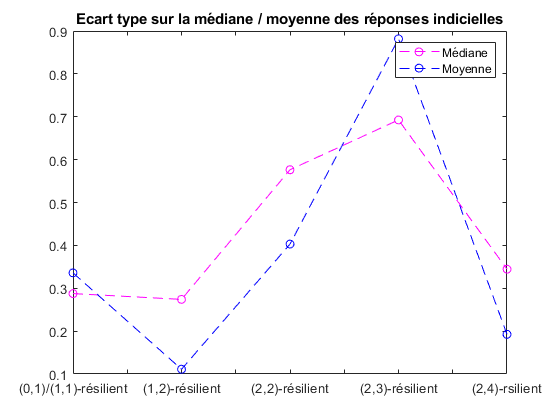

EC_MED_FIABLE = [std_med_fiable_11 std_med_fiable_12 std_med_fiable_22 std_med_fiable_23 std_med_fiable_24];
EC_M_FIABLE = [std_m_fiable_11 std_m_fiable_12 std_m_fiable_22 std_m_fiable_23 std_m_fiable_24];

EC_MED = [std_med_11 std_med_12 std_med_22 std_med_23 std_med_24];
EC_M = [std_m_11 std_m_12 std_m_22 std_m_23 std_m_24];

figure
plot(EC_MED_FIABLE, 'm--o'); hold on;
plot(EC_M_FIABLE, 'b--o');
title("Ecart type sur la médiane / moyenne des réponses indicielles");
legend('Médiane', 'Moyenne');
ax = gca;
ax.XTickLabel = ({'(0,1)/(1,1)-résilient', ' ', '(1,2)-résilient', ' ', '(2,2)-résilient', ' ', '(2,3)-résilient', ' ', '(2,4)-rsilient'});

% figure
% plot(EC_MED, 'mo'); hold on;
% plot(EC_M, 'bo');
% title("Standard deviation on median / mean step response");
% legend('Median', 'Mean');
% ax = gca;
% ax.XTickLabel = ({'(0,1)/(1,1)-resilient', ' ', '(1,2)-resilient', ' ', '(2,2)-resilient', ' ', '(2,3)-resilient', ' ', '(2,4)-resilient'});



% med_global_step = zeros(4, length(med_step_14));
% for a=1:1:length(med_step_14)
%     med_global_step(1,a) = med_step_11(3,a);
%     med_global_step(2,a) = med_step_12(3,a);
%     med_global_step(3,a) = med_step_13(5,a);
%     med_global_step(4,a) = med_step_14(5,a);
% end


### PLOT OF STEP RESPONSES

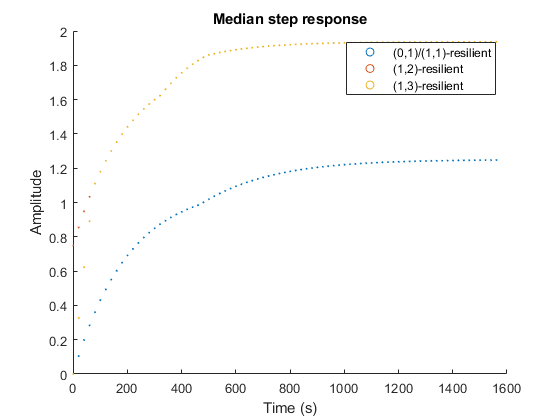


x11_med = 1:20:1564;
y11_med = med_step_11(3,x11_med);

x12_med = 1:20:1564;
y12_med = med_step_12(3,x12_med);

x22_med = 1:20:1564;
y22_med = med_step_22(3,x22_med);

x13_med = 1:20:1564;
y13_med = med_step_13(3,x13_med);

x14_med = 1:20:1564;
y14_med = med_step_14(3,x14_med);

x23_med = 1:20:1564;
y23_med = med_step_23(5,x23_med);

x24_med = 1:20:1564;
y24_med = med_step_24(5,x24_med);


x11_m = 1:20:1564;
y11_m = m_step_11(3,x11_m);

x12_m = 1:20:1564;
y12_m = m_step_12(3,x12_m);

x22_m = 1:20:1564;
y22_m = m_step_22(5,x22_m);

x13_m = 1:20:1564;
y13_m = m_step_13(3,x13_m);

x14_m = 1:20:1564;
y14_m = m_step_14(3,x14_m);

x23_m = 1:20:1564;
y23_m = m_step_23(5,x23_m);

x24_m = 1:20:1564;
y24_m = m_step_24(5,x24_m);


% FIABLE



x11_med_fiable = 1:20:length(Step11);
y11_med_fiable = fiable_med_step_11(1,x11_med_fiable);

x11_m_fiable = 1:1:length(Step11);
y11_m_fiable = fiable_m_step_11(1,x11_m_fiable);

x11_m_fiable_r = 1:1:length(Step11);
y11_m_fiable_r = fiable_m_step_11(1,x11_m_fiable_r);

x12_med_fiable = 1:20:length(Step22);
y12_med_fiable = fiable_med_step_12(1,x12_med_fiable);

x12_m_fiable = 1:1:length(Step22);
y12_m_fiable = fiable_m_step_12(1,x12_m_fiable);

x12_m_fiable_r = 1:1:length(Step22);
y12_m_fiable_r = fiable_m_step_12(1,x12_m_fiable_r);

x13_med_fiable = 1:20:length(Step22);
y13_med_fiable = fiable_med_step_13(1,x13_med_fiable);

x13_m_fiable = 1:1:length(Step22);
y13_m_fiable = fiable_m_step_13(1,x13_m_fiable);

x13_m_fiable_r = 1:1:length(Step22);
y13_m_fiable_r = fiable_m_step_13(1,x13_m_fiable_r);

x14_med_fiable = 1:20:length(Step22);
y14_med_fiable = fiable_med_step_14(1,x14_med_fiable);

x14_m_fiable = 1:1:length(Step22);
y14_m_fiable = fiable_m_step_14(1,x14_m_fiable);

x14_m_fiable_r = 1:1:length(Step22);
y14_m_fiable_r = fiable_m_step_14(1,x14_m_fiable_r);

x22_med_fiable = 1:20:length(Step22);
y22_med_fiable = fiable_med_step_22(1,x22_med_fiable);

x22_m_fiable = 1:1:length(Step22);
y22_m_fiable = fiable_m_step_22(1,x22_m_fiable);

x22_m_fiable_r = 1:1:length(Step22);
y22_m_fiable_r = fiable_m_step_22(1,x22_m_fiable_r);

x23_med_fiable = 1:20:length(Step22);
y23_med_fiable = fiable_med_step_23(1,x23_med_fiable);

x23_m_fiable = 1:1:length(Step22);
y23_m_fiable = fiable_m_step_23(1,x23_m_fiable);

x23_m_fiable_r = 1:1:length(Step22);
y23_m_fiable_r = fiable_m_step_23(1,x23_m_fiable_r);

x24_med_fiable = 1:20:length(Step22);
y24_med_fiable = fiable_med_step_24(1,x24_med_fiable);

x24_m_fiable = 1:1:length(Step22);
y24_m_fiable = fiable_m_step_24(1,x24_m_fiable);

x24_m_fiable_r = 1:1:length(Step22);
y24_m_fiable_r = fiable_m_step_24(1,x24_m_fiable_r);



figure 
scatter(x11_med_fiable, y11_med_fiable, 1); hold on;
scatter(x12_med_fiable, y12_med_fiable, 1); hold on;
scatter(x13_med_fiable, y13_med_fiable, 1); %hold on;
%scatter(x14_med_fiable, y14_med_fiable, 1);
title('Median step response');
xlabel('Time (s)');
ylabel('Amplitude');
legend('(0,1)/(1,1)-resilient', '(1,2)-resilient', '(1,3)-resilient');

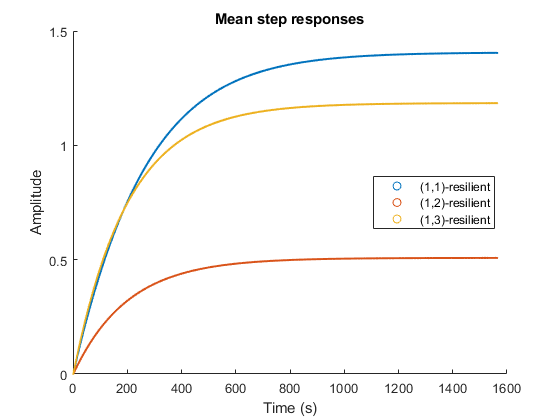


figure 
scatter(x11_m_fiable, y11_m_fiable, 1); hold on;
scatter(x12_m_fiable, y12_m_fiable-1.25, 1); hold on;
scatter(x13_m_fiable, y13_m_fiable-0.8333, 1); %hold on;
%scatter(x14_med_fiable, y14_med_fiable, 1);
title('Mean step responses');
xlabel('Time (s)');
ylabel('Amplitude');
legend({'(1,1)-resilient', '(1,2)-resilient', '(1,3)-resilient'}, 'Location','best');

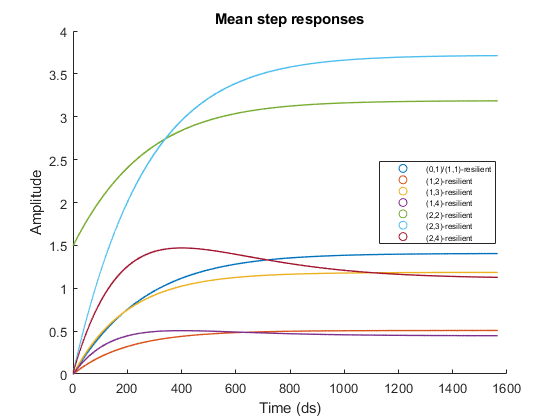


%stepinfo(SYS_t11_d(1,1))
figure 
scatter(x11_m_fiable, y11_m_fiable, 0.3); hold on;
scatter(x12_m_fiable, y12_m_fiable-1.25, 0.3); hold on;
scatter(x13_m_fiable, y13_m_fiable-0.833, 0.3); hold on;
scatter(x14_m_fiable, y14_m_fiable-0.624, 0.3); hold on;
scatter(x22_m_fiable, y22_m_fiable-0.5, 0.3); hold on;
scatter(x23_m_fiable, y23_m_fiable-0.3144, 0.3); hold on;
scatter(x24_m_fiable, y24_m_fiable-0.2515, 0.3);
title('Mean step responses');
xlabel('Time (ds)');
ylabel('Amplitude');
legend({'(0,1)/(1,1)-resilient', '(1,2)-resilient', '(1,3)-resilient', '(1,4)-resilient', '(2,2)-resilient', '(2,3)-resilient', '(2,4)-resilient'}, 'Location','east', 'FontSize',6);

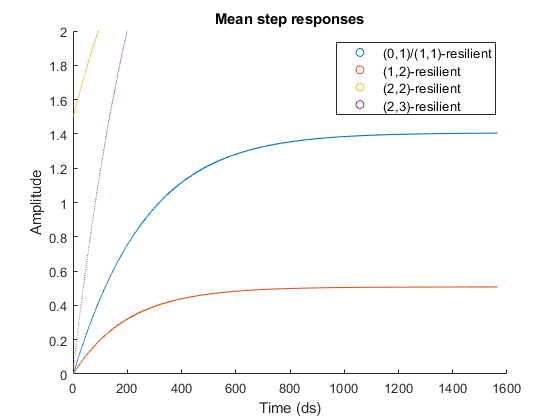

figure 
scatter(x11_m_fiable, y11_m_fiable, 0.1); hold on;
scatter(x12_m_fiable, y12_m_fiable-1.25, 0.1); hold on;
scatter(x22_m_fiable, y22_m_fiable-0.5, 0.1); hold on;
scatter(x23_m_fiable, y23_m_fiable-0.3144, 0.1);
title('Mean step responses');
xlabel('Time (ds)');
ylabel('Amplitude');
ylim([0 2]);
legend({'(0,1)/(1,1)-resilient', '(1,2)-resilient', '(2,2)-resilient', '(2,3)-resilient'}, 'Location','northeast', 'FontSize',10);

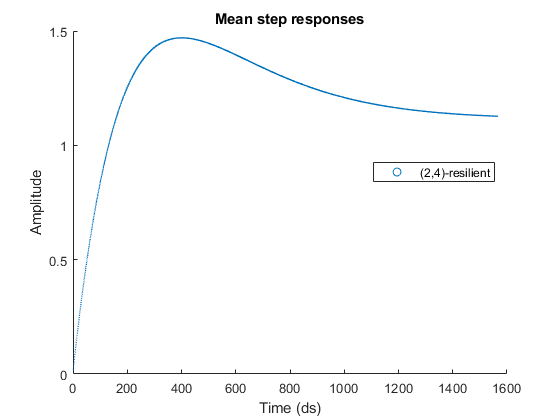

figure 
scatter(x24_m_fiable, y24_m_fiable-0.2515, 0.3);
title('Mean step responses');
xlabel('Time (ds)');
ylabel('Amplitude');
legend({'(2,4)-resilient'}, 'Location','best');

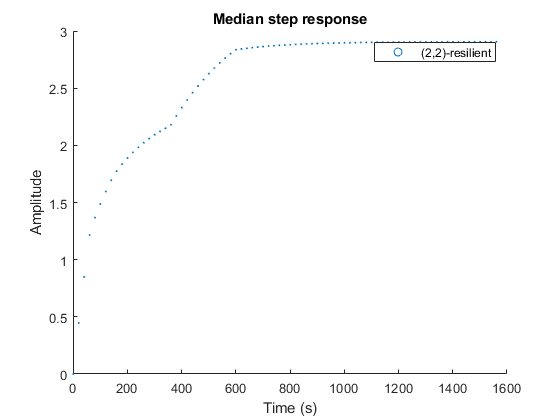


figure
scatter(x22_med_fiable, y22_med_fiable, 1);
title('Median step response');
xlabel('Time (s)');
ylabel('Amplitude');
legend('(2,2)-resilient');

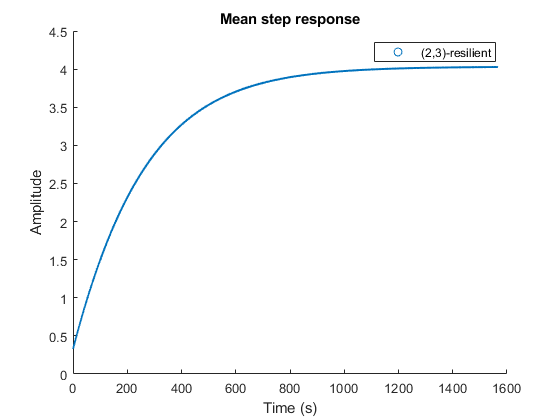

figure
scatter(x23_m_fiable, y23_m_fiable, 1);
title('Mean step response');
xlabel('Time (s)');
ylabel('Amplitude');
legend('(2,3)-resilient');

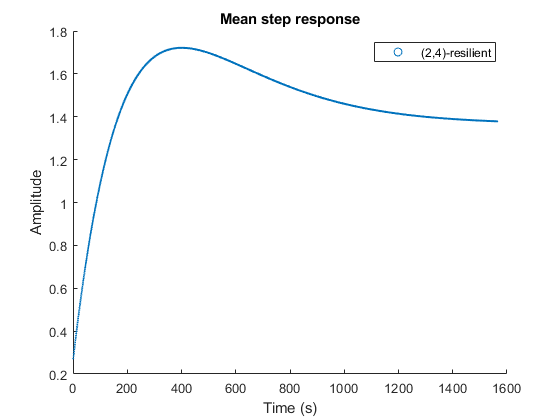


figure
scatter(x24_m_fiable, y24_m_fiable, 1);
title('Mean step response');
xlabel('Time (s)');
ylabel('Amplitude');
legend('(2,4)-resilient');

### RISE TIME, RESPONSE TIME, DELAY TIME

MEAN_RISE_TIME_11 = (43.9 + 67.1 + 67.1 + 43.9 + 43.9 + 43.9) / 6

MEAN_RISE_TIME_11 = 51.6333

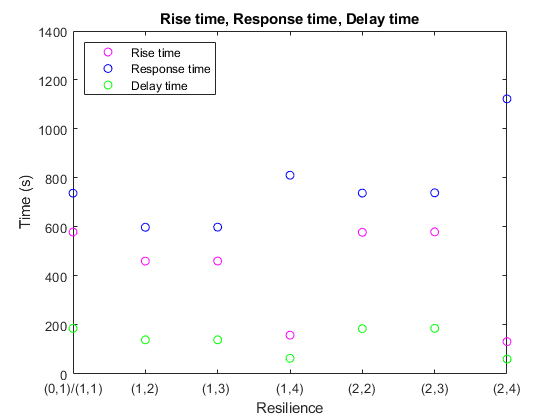

% stepinfo(SYS_t11_d(1,1))
% stepinfo(SYS_t11_d(1,2))
% stepinfo(SYS_t11_d(2,1))
% stepinfo(SYS_t11_d(2,2))
% stepinfo(SYS_t11_d(3,1))
% stepinfo(SYS_t11_d(3,2))
% stepinfo(SYS_t11_d(4,1))
% stepinfo(SYS_t11_d(4,2))



T_MONTEE = [579.5 460.9 461.2 158.5 578.5 580 132.1];
T_REPONSE = [738 599 599.5 811.4 738.5 739.5 1123];
T_RETARD = [186.3 139.6 139.5 64 185  186.5 60.9];
DEPASS = [0 0 0 0.0544 0 0 0.0937];

figure
plot(T_MONTEE, 'mo'); hold on;
plot(T_REPONSE, 'bo'); hold on;
plot(T_RETARD, 'go');
title('Rise time, Response time, Delay time');
xlabel('Resilience');
ylabel('Time (s)');
legend({'Rise time', 'Response time', 'Delay time'}, 'Location', 'northwest');
ax = gca;
ax.XTickLabel = ({'(0,1)/(1,1)', '(1,2)', '(1,3) ', '(1,4)', '(2,2)', '(2,3)', '(2,4)'});
%xlim([0 7])
ylim([0 1400])

### OVERTAKING

figure
plot(DEPASS, 'ro');
title('Overtaking');
xlabel('Resilience');
ylabel('Relative value');
legend({'Overtaking'}, 'Location','northwest');
ax = gca;
ax.XTickLabel = ({'(0,1)/(1,1)', '(1,2)', '(1,3) ', '(1,4)', '(2,2)', '(2,3)', '(2,4)'});
%xlim([0.67 5.45])
ylim([-0.01 0.12])

### ANSWER TO STABILITY : all our systems are stable

answer11 = isstable(SYS_t11_d)

answer11 = logical
   1


answer12 = isstable(SYS_t12_d)

answer12 = logical
   1


answer13 = isstable(SYS_t13_d)

answer13 = logical
   1


answer14 = isstable(SYS_t14_d)

answer14 = logical
   1


answer22 = isstable(SYS_t22_d)

answer22 = logical
   1


answer23 = isstable(SYS_t23_d)

answer23 = logical
   1


answer24 = isstable(SYS_t24_d)

answer24 = logical
   1


### BODE

% figure
% for i=1:1:4
%     for j=1:1:2
%         bode(SYS_t11_d(i,j)); hold on;
%     end
% end
% title("Bode Diagram : SYS (0,1)/(1,1)-resilient");
% figure
% for i=1:1:8
%     for j=1:1:2
%         bode(SYS_t12_d(i,j)); hold on;
%     end
% end
% title("Bode Diagram : SYS (1,2)-resilient");
% figure
% for i=1:1:8
%     for j=1:1:4
%         bode(SYS_t22_d(i,j)); hold on;
%     end
% end
% title("Bode Diagram : SYS (2,2)-resilient");

### NYQUIST DIAGRAM : here we compute the mean gain margin (stability degree) of each system

The data were obtained by graphically reading the Nyquist diagrams.

**It takes several minutes for the calculations to be completed, especially the for the (2,4)-resilient system**

% (1,1)-resilient

% figure
% for i=1:1:4
%     for j=1:1:2
%         nyquist(SYS_t11_d(i,j)); hold on;
%     end
% end
% title("Nyquist Diagram disc : SYS (0,1)/(1,1)-resilient");
result11 = (20*log10(1/5.469e-3)+20*log10(1/3.906e-3)+20*log10(1/2.344e-3)+20*log10(1/1.93e-3)+20*log10(1/1.16e-3))/5

result11 = 51.8015

% (1,2)-resilient

% figure
% for i=1:1:8
%     for j=1:1:2
%         nyquist(SYS_t12_d(i,j)); hold on;
%     end
% end
% title("Nyquist Diagram : SYS (1,2)-resilient");
result12 = (20*log10(1/5.469e-3)+20*log10(1/3.906e-3)+20*log10(1/2.344e-3)+20*log10(1/1.93e-3)+20*log10(1/1.16e-3))/5

result12 = 51.8015

% (2,2)-resilient

% figure
% for i=1:1:8
%     for j=1:1:4
%        nyquist(SYS_t22_d(i,j)); hold on;
%     end
% end
% title("Nyquist Diagram : SYS (2,2)-resilient");
sans_vert_22 = (20*log10(1/1.95e-3)+20*log10(1/1.15e-3)+20*log10(1/2.5e-5)+20*log10(1/1.6e-5)) / 4

sans_vert_22 = 75.2360

result22 = (20*log10(1/0.005469)+20*log10(1/0.003906)+20*log10(1/0.00234)+20*log10(1/1.95e-3)+20*log10(1/1.15e-3)+20*log10(1/5.121e-5)+20*log10(1/3.269e-5)+20*log10(1/2.5e-5)+20*log10(1/1.6e-5)+20*log10(1/2.695e-6)+20*log10(1/2.461e-6)+20*log10(1/1.628e-8)+20*log10(1/9.766e-9)+20*log10(1/2.134e-10)+20*log10(1/1.362e-10))/15

result22 = 103.5176

% (1,3)-resilient

% figure
% for i=1:1:12
%     for j=1:1:2
%         nyquist(SYS_t13_d(i,j)); hold on;
%     end
% end
% title("Nyquist Diagram : SYS (1,3)-resilient");
result13 = (20*log10(1/0.01367)+20*log10(1/9.766e-3)+20*log10(1/5.859e-3)+20*log10(1/5.469e-3)+20*log10(1/3.906e-3)+20*log10(1/2.344e-3)+20*log10(1/4.817e-3)+20*log10(1/2.89e-3)+20*log10(1/1.927e-3)+20*log10(1/1.156e-3))/10

result13 = 47.8312

% (2,3)-resilient

% figure
% for i=1:1:12
%     for j=1:1:4
%         nyquist(SYS_t23_d(i,j)); hold on;
%     end
% end
% title("Nyquist Diagram : SYS (2,3)-resilient");
sans_vert_23 = (20*log10(1/5e-3)+20*log10(1/2.9e-3)+20*log10(1/1.95e-3)+20*log10(1/1.15e-3)+20*log10(1/6e-5)+20*log10(1/4e-5)+20*log10(1/2.8e-5)+20*log10(1/1.7e-5)) / 8

sans_vert_23 = 71.0752

result23 = (20*log10(1/0.01367)+20*log10(1/0.009766)+20*log10(1/0.005859)+20*log10(1/0.005469)+20*log10(1/0.003906)+20*log10(1/0.002344)+20*log10(1/5e-3)+20*log10(1/2.9e-3)+20*log10(1/1.95e-3)+20*log10(1/1.15e-3)+20*log10(1/13e-5)+20*log10(1/8e-5)+20*log10(1/5e-5)+20*log10(1/6e-5)+20*log10(1/4.5e-5)+20*log10(1/4e-5)+20*log10(1/3e-5)+20*log10(1/2.8e-5)+20*log10(1/7e-6)+20*log10(1/6e-6)+20*log10(1/3e-6)+20*log10(1/2.5e-6)+5*20*log10(1/2e-8))/27

result23 = 87.5688

% (1,4)-resilient

% figure
% for i=1:1:24
%     for j=1:1:4
%         nyquist(SYS_t14_d(i,j)); hold on;
%     end
% end
% title("Nyquist Diagram : SYS (1,4)-resilient");
result14 = (20*log10(1/0.01367)+20*log10(1/9.766e-3)+20*log10(1/5.859e-3)+20*log10(1/5.469e-3)+20*log10(1/3.906e-3)+20*log10(1/2.344e-3)+20*log10(1/4.817e-3)+20*log10(1/2.89e-3)+20*log10(1/2.409e-3)+20*log10(1/1.927e-3)+20*log10(1/1.445e-3)+20*log10(1/1.156e-3)+20*log10(1/9.635e-4)+20*log10(1/5.781e-4)+20*log10(1/0.9375)+20*log10(1/0.9375004)+20*log10(1/1.5625)+20*log10(1/1.5625006)+20*log10(1/2.1875)+2*20*log10(1/2.3438)+2*20*log10(1/3.906)+20*log10(1/5.4688)) / 24 % on fait 22+2

result14 = 26.9127


% (2,4)-resilient

% figure
% for i=1:1:24
%     for j=1:1:8
%         nyquist(SYS_t24_d(i,j)); hold on;
%     end
% end
% title("Nyquist Diagram : SYS (2,4)-resilient");


result24 = (20*log10(1/5.469)+2*20*log10(1/3.9)+2*20*log10(1/2.3)+20*log10(1/2.1)+2*20*log10(1/1.5)+20*log10(1/0.9375)+20*log10(1/0.05)+20*log10(1/0.03)+20*log10(1/0.02)+20*log10(1/0.014)+20*log10(1/0.013)+20*log10(1/0.01)+2*20*log10(1/0.005)+20*log10(1/5e-3)+20*log10(1/4e-3)+20*log10(1/3e-3)+20*log10(1/0.002695)+3*20*log10(1/0.002458)+20*log10(1/2e-3)+20*log10(1/1.5e-3)+4*20*log10(1/1.15e-3)+20*log10(1/0.8e-3)+20*log10(1/13e-5)+20*log10(1/8e-5)+20*log10(1/6e-5)+20*log10(1/6e-5)+20*log10(1/5e-5)+20*log10(1/4e-5)+2*20*log10(1/3e-5)+20*log10(1/2.5e-5)+20*log10(1/2e-5)+20*log10(1/1.75e-5)+20*log10(1/1.3e-5)+20*log10(1/0.9e-5)+2*20*log10(1/0.8e-5)+2*20*log10(1/0.25e-3)+20*log10(1/0.8e-7)+20*log10(1/0.5e-7)+20*log10(1/0.4e-7)+20*log10(1/0.35e-7)+20*log10(1/0.25e-7)+20*log10(1/2e-8)+20*log10(1/1.6e-8)+20*log10(1/1e-8)+20*log10(1/11e-10)+20*log10(1/6e-10)+20*log10(1/5e-10)+20*log10(1/4.2e-10)+20*log10(1/3.4e-10)+20*log10(1/2.7e-10)+20*log10(1/2.1e-10)+20*log10(1/1.3e-10))/64

result24 = 81.5433

### STABILITY OF EIGENVALUES

real_part_A11 = real(eig(A11))

real_part_A11 =    -0.0500
   -0.0500
   -0.0500
   -0.0500


real_part_A12 = real(eig(A12))

real_part_A12 =    -0.0500
   -0.0500
   -0.0500
   -0.0500


real_part_A13 = real(eig(A13))

real_part_A13 =    -0.0500
   -0.0500
   -0.0500
   -0.0500


### ÉQUATION AUX DÉRIVÉES PARTIELLES

%syms alpha gamma k v a h0 Delta
syms h Delta % liquid level vs. time (cm)
alpha = 32; % tank cross sectional area (cm^2) 
gamma = 0.6; % valve coefficient
k = 3; % pump coefficient (cm^3/Vs)
v = 5; % pump volateg (V)
a = 4; % outlet valve coefficient
h0 = 1.5625;

%de = [diff(h) == (gamma*k*v)/(alpha) - (a*sqrt(h0)*(1+(Delta/(2*h0))))/(alpha)]
h = (gamma*k*v)/(alpha) - (a*sqrt(h0)*(1+(Delta/(2*h0))))/(alpha)

$$h = \frac{1}{8}-\frac{\Delta }{20}$$

% df1=diff(h,'alpha')
% df2=diff(h,'gamma')
% df3=diff(h,'k')
% df4=diff(h,'v')
% df5=diff(h,'a')
% df6=diff(h,'h0')
syms s
F = 4/(s*s+4*s+5);
ilaplace(F)

$$ans = 4\,{\mathrm{e}}^{-2\,t}\,\sin\left(t\right)$$

%NOEUD STABLE
A1=[-2 1; 1 -2];
poly(A1);
p1 = [1 4 3];
r1 = roots(p1)

r1 =     -3
    -1


[V1,D1] = eig(A1) 

V1 =     0.7071    0.7071
   -0.7071    0.7071


D1 =     -3     0
     0    -1


% figure
% plot([-0.7071 0.7071]); hold on;
% plot(transpose([0.7071 0.7071]));
A2=[2 1; 2 3];
poly(A2);
p2 = [1 -5 4];
r2 = roots(p2)

r2 =      4
     1


[V2,D2] = eig(A2)

V2 =    -0.7071   -0.4472
    0.7071   -0.8944


D2 =      1     0
     0     4


% figure
% plot(transpose([-0.7071 0.7071])); hold on;
% plot(transpose([-0.4472 -0.8944]));
poly(A11)

ans =     1.0000    0.2000    0.0150    0.0005    0.0000


p11 = [1 0.2 0.015 0.0005 0.0];
r11 = roots(p11)

r11 =    0.0000 + 0.0000i
  -0.1000 + 0.0000i
  -0.0500 + 0.0500i
  -0.0500 - 0.0500i


[V11,D11] = eig(A11)

V11 =     1.0000         0   -1.0000         0
         0    1.0000         0   -1.0000
         0         0    0.0000         0
         0         0         0    0.0000


D11 =    -0.0500         0         0         0
         0   -0.0500         0         0
         0         0   -0.0500         0
         0         0         0   -0.0500


[V12,D12] = eig(A12)

V12 =     1.0000         0   -1.0000         0
         0    1.0000         0   -1.0000
         0         0    0.0000         0
         0         0         0    0.0000


D12 =    -0.0500         0         0         0
         0   -0.0500         0         0
         0         0   -0.0500         0
         0         0         0   -0.0500


[V13,D13] = eig(A13)

V13 =     1.0000         0   -1.0000         0
         0    1.0000         0   -1.0000
         0         0    0.0000         0
         0         0         0    0.0000


D13 =    -0.0500         0         0         0
         0   -0.0500         0         0
         0         0   -0.0500         0
         0         0         0   -0.0500


[V14,D14] = eig(A14)

V14 =     1.0000         0   -1.0000         0    1.0000         0   -1.0000         0
         0    1.0000         0   -1.0000         0    1.0000         0   -1.0000
         0         0    0.0000         0         0         0    0.0000         0
         0         0         0    0.0000         0         0         0    0.0000
         0         0         0         0    0.0000         0   -0.0000         0
         0         0         0         0         0    0.0000         0   -0.0000
         0         0         0         0         0         0    0.0000         0
         0         0         0         0         0         0         0    0.0000


D14 =    -0.0500         0         0         0         0         0         0         0
         0   -0.0500         0         0         0         0         0         0
         0         0   -0.0500         0         0         0         0         0
         0         0         0   -0.0500         0         0         0         0
         0         0         0         0   -0.0500         0         0         0
         0         0         0         0         0   -0.0500         0         0
         0         0         0         0         0         0   -0.0500         0
         0         0         0         0         0         0         0   -0.0500


[V22,D22] = eig(A22)

V22 =     1.0000         0   -1.0000         0
         0    1.0000         0   -1.0000
         0         0    0.0000         0
         0         0         0    0.0000


D22 =    -0.0500         0         0         0
         0   -0.0500         0         0
         0         0   -0.0500         0
         0         0         0   -0.0500


[V23,D23] = eig(A23)

V23 =     1.0000         0   -1.0000         0
         0    1.0000         0   -1.0000
         0         0    0.0000         0
         0         0         0    0.0000


D23 =    -0.0500         0         0         0
         0   -0.0500         0         0
         0         0   -0.0500         0
         0         0         0   -0.0500


% figure
% pz11 = iopzplot(SYS_t11_d); 
% setoptions(pz11,'IOGrouping','all');
% legend('SYS (1,1)-RESILIENT');
% axis([-1.5, 1.5 -1.25 1.25])

% figure
% pz12 = iopzplot(SYS_t12_d); 
% setoptions(pz12,'IOGrouping','all');
% legend('SYS (1,2)-RESILIENT');
% axis([-1.5, 1.5 -1.25 1.25])

% figure
% pz13 = iopzplot(SYS_t13_d); 
% setoptions(pz13,'IOGrouping','all');
% legend('SYS (1,3)-RESILIENT');
% axis([-1.5, 1.5 -1.25 1.25])

% figure
% pz14 = iopzplot(SYS_t14_d); 
% setoptions(pz14,'IOGrouping','all');
% legend('SYS (1,4)-RESILIENT');
% axis([-1.5, 1.5 -1.25 1.25])

% figure
% iopzplot(SYS_t22_d); 
% setoptions(iopzplot(SYS_t22_d),'IOGrouping','all');
% legend('SYS (2,2)-RESILIENT');
%axis([-1.5, 1.5 -1.25 1.25])

% figure
% iopzplot(SYS_t23_d); 
% setoptions(iopzplot(SYS_t23_d),'IOGrouping','all');
% legend('SYS (2,3)-RESILIENT');
%axis([-1.5, 1.5 -1.25 1.25])


### OBSERVABILITY MATRIX

OB_PETIT = obsv(A_base,C_base)

OB_PETIT =     1.0000
         0
    1.6000


OB11 = obsv(A11,C11);
OB12 = obsv(A12,C12);
OB13 = obsv(A13,C13);
OB14 = obsv(A14,C14);
OB22 = obsv(A22,C22);
OB23 = obsv(A23,C23);
OB24 = obsv(A24,C24);
rank(OB_PETIT)

ans = 1

rank(OB11)

ans = 4

rank(OB12)

ans = 4

rank(OB13)

ans = 4

rank(OB14)

ans = 8

rank(OB22)

ans = 4

rank(OB23)

ans = 4

rank(OB24)

ans = 8

### CDF

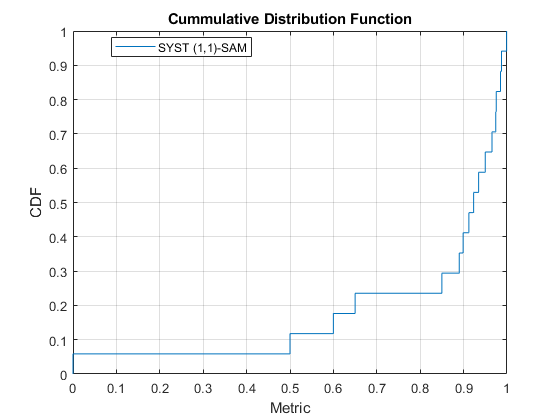

figure
y = [0 0.5 0.6 0.65 0.85 0.89 0.899 0.9123 0.923 0.9345 0.95 0.9654 0.9741 0.9753 0.98741 0.985 0.999];
%[0.25 0.5 0.667 0.667 0.5 0.667 0.667];
cdfplot(y)
title('Cummulative Distribution Function');
xlabel('Metric');
ylabel('CDF');
legend({'SYST (1,1)-SAM'}, 'Location','best');

uk = [.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 .5 1 1 1 1 1 1 1 1 1 1 1 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5 1.5].'

uk =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


% figure
% plot(uk)
% load('D:/TRAVAIL IMT/Romain/Etude expérimentale/DATA_y_PETIT_ATTACKED.mat');
% y_PETIT_attacked
% load('D:/TRAVAIL IMT/Romain/Etude expérimentale/DATA_x_PETIT.mat');
% x_PETIT

### Q ERROS ARE CORRECTABLE FOR (A,C) AFTER N STEPS

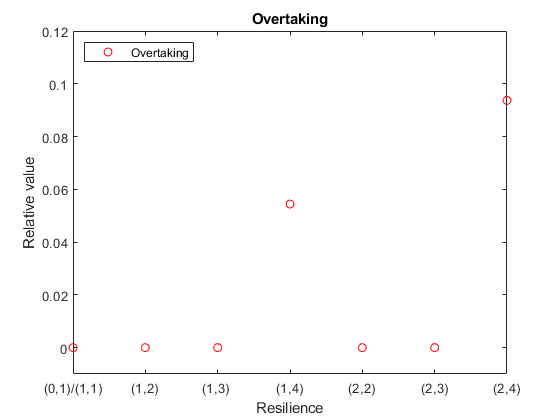

% nnz(C_base*eig(A_base)) % PETIT
% nnz(C11*eig(A11)) % (1,1)
% nnz(C12*eig(A12)) % (1,2)
% nnz(C13*eig(A13)) % (1,3)
% nnz(C14*eig(A14)) % (1,4)
% nnz(C22*eig(A22)) % (2,2)
% nnz(C23*eig(A23)) % (2,3)
% nnz(C24*eig(A24)) % (2,4)
% phi_PETIT = OB_PETIT.*x_PETIT(3,1)
%x = decoder(y_PETIT_attacked, 1, phi_PETIT, 3, 1);

save('romain_SYST');

% function norm_l1_lr = l1_lr(M,np)
%     for i=1:1:np
%         %l2 = max(svd(M(i,:)));
%         %matL2 = norm(M(i,:),2);
%         norm_l1_lr = norm_l1_lr + norm(M(i,:),2);
%     end
% end
% 
% function x_recov = decoder(y,T,phi,np,nn)
%     x_recov = arg(min(norm_l1_lr((y-(phi.*rand(3,1))),np)));
% end